Look at histograms - Tue

Look at 12 hours of data with fixed peak time

More channels before peak

How to fix the peak: fix the mean peak channel at 0 and use certain channels pre and post-peak for lifetime calculation over 12 hours. (write in the protocol)

Sleep analysis

Pick 12 hours data, show the raw data, the filter data

Align the histograms together from different experiments across diff mice, diff states

- Use more channels before the peak. Previously I was using 3 channels before the peak. This time I changed it to 20. In spc_fitPostCalcs.m I made the modification:

if FixPeakChannel==1

        lft_points=[-19:1:149]*nsPerPoint;

        peak_point=peak_point_define;

        empirical_lifetimes=spc.lifetimes{chan}((peak_point-20):(peak_point+148));

        spc.fits{chan}.EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

    else

I'm using the FLP dataset 122221_1521_1_005 to test this out: 


global FixPeakChannel peak_point_define

FixPeakChannel=1;
peak_point_define=42;

ExperimentName='122221_1521_1_005'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[14 15 16 17 18 19 20 21 22 23 24 25 26]

Dark_hours =     14    15    16    17    18    19    20    21    22    23    24    25    26


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220228_fixpeak.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end



global FixPeakChannel peak_point_define

FixPeakChannel=1;
peak_point_define=42;

ExperimentName='122221_1521_1_005'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[14 15 16 17 18 19 20 21 22 23 24 25 26]

Dark_hours =     14    15    16    17    18    19    20    21    22    23    24    25    26


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


% 20220306_flexbiepeak: flexible peak; 20 channels pre-peak; 148 channels
% post peak
% 20220228_fixpeak: fix peak at 42; 20 channels pre-peak; 148 channels
% post peak
% 20220228_flexiblepeak: flexible peak; 20 channels pre-peak; 148 channels
% post peak
% 20220306_NoPrePeak: fix peak at 42; 0 channels pre-peak; 148 channels
% post peak

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220306_NoPrePeak.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

Matrix dimensions must agree.

Error in spc_fitPostCalcs (line 66)
        spc.fits{chan}.EmpTauTrunc=sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes); % calculation of empirical lifetime, Pingchuan added 06.28.21

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('spc_fitexp2gaussGY', '/Users/pingchuanma/Documents/MATLAB/MatlabCode/FLP_code_fromSJ/FLP code_20180807/FLP_MATLAB code/MATLAB_FLIMmultiboard/zFLIM/fit/spc_fitexp2gaussGY.m', 30)" style="font-weight:bold">spc_fitexp2gaussGY<

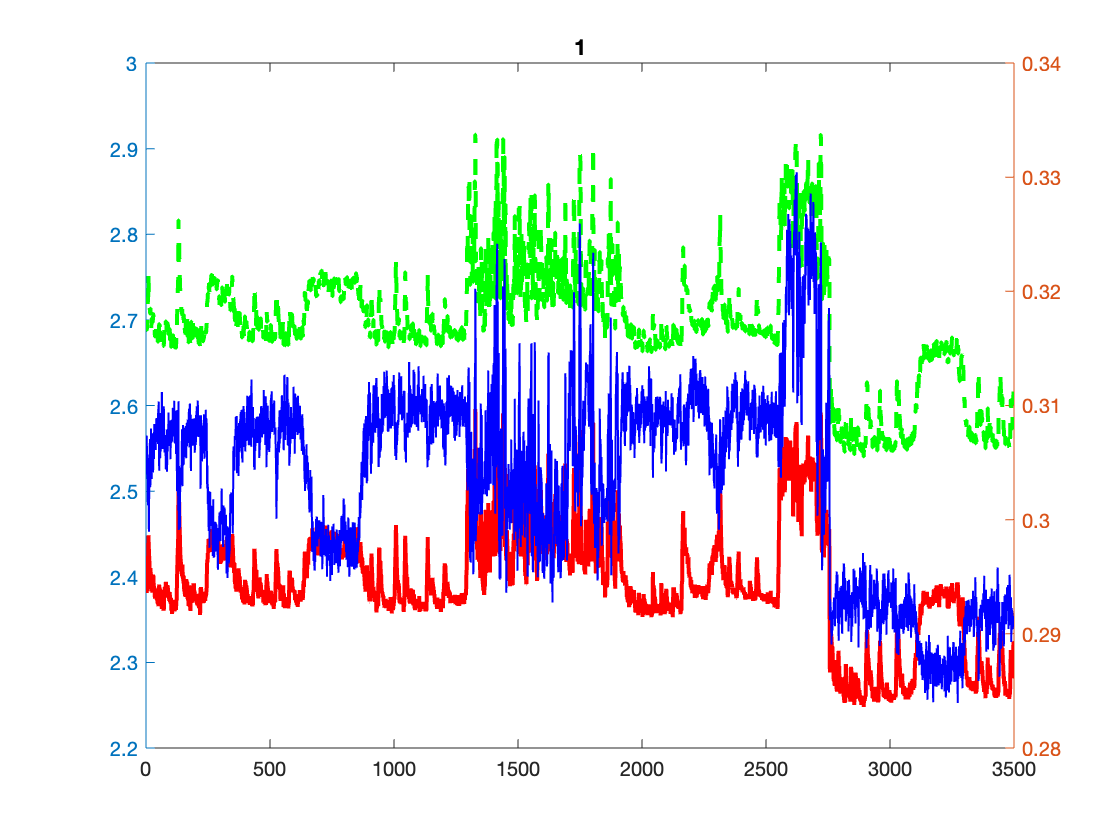

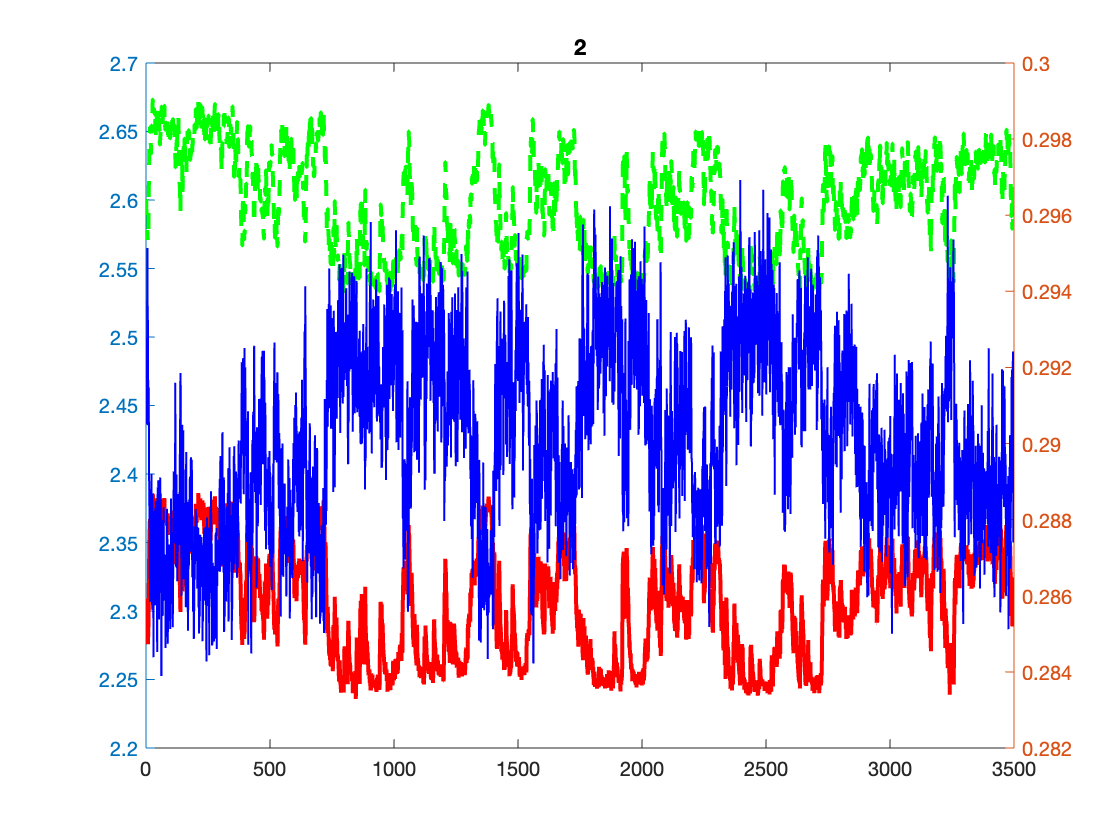

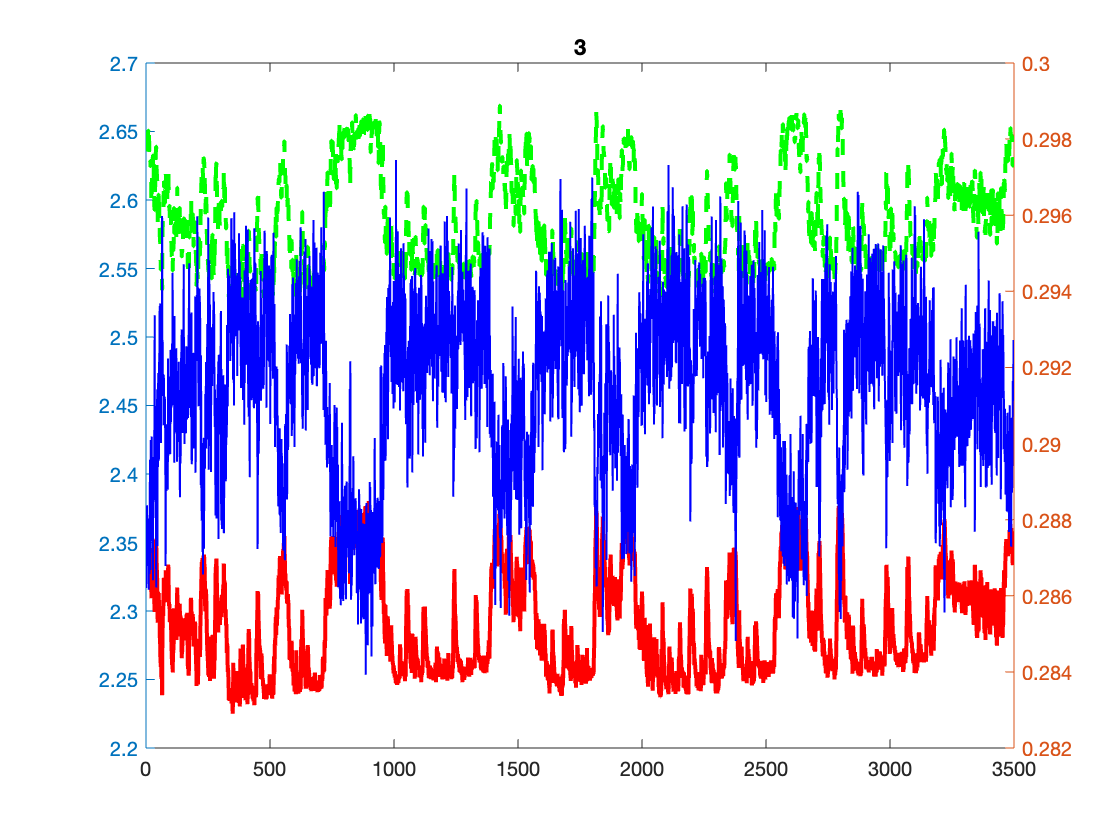

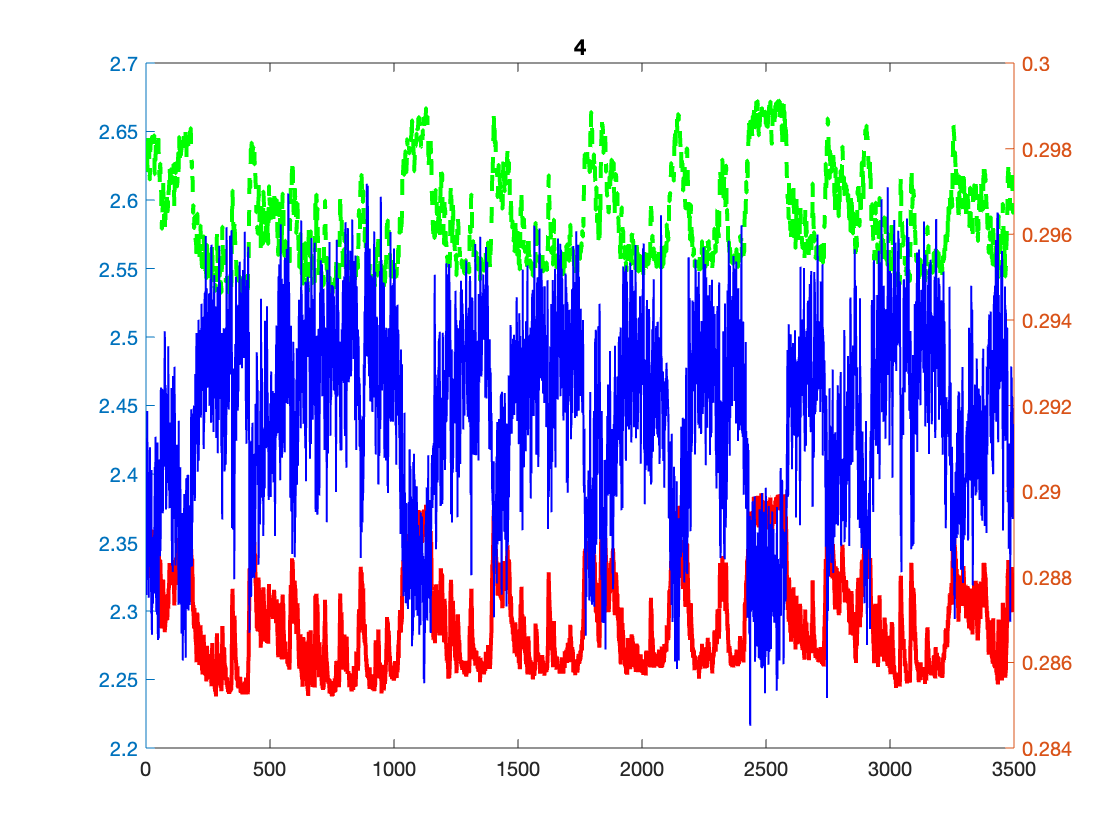

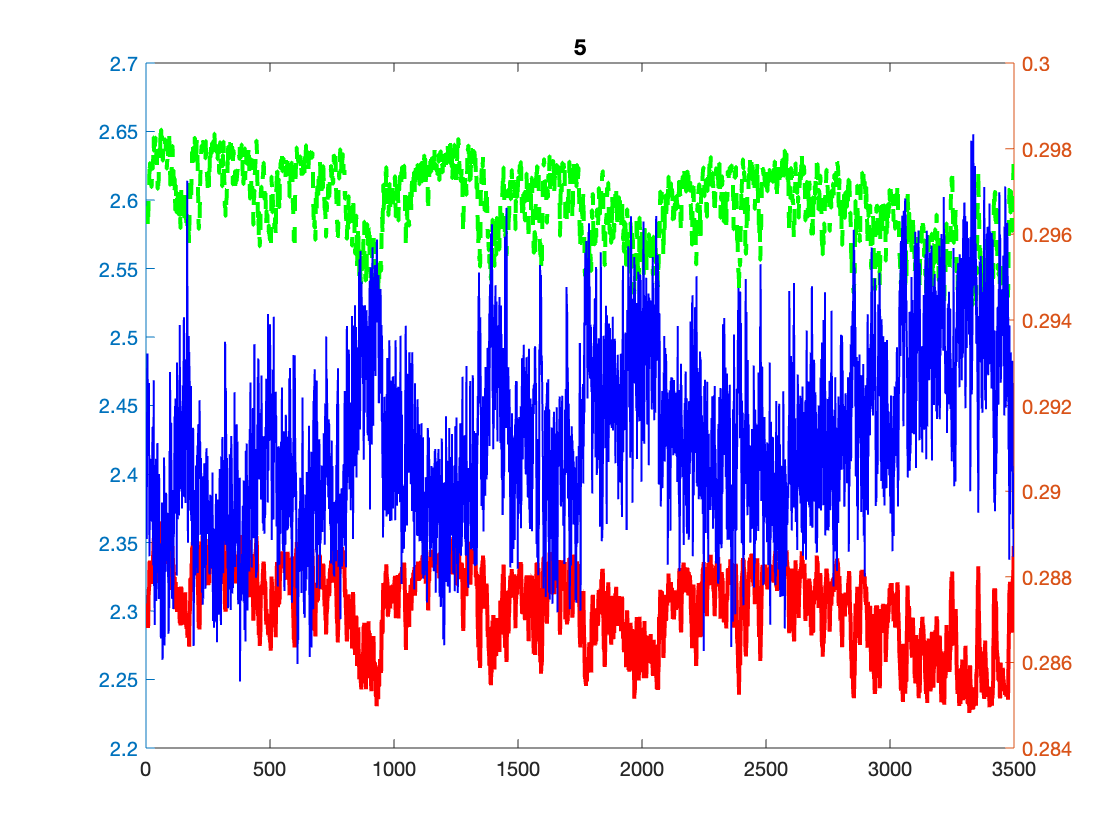

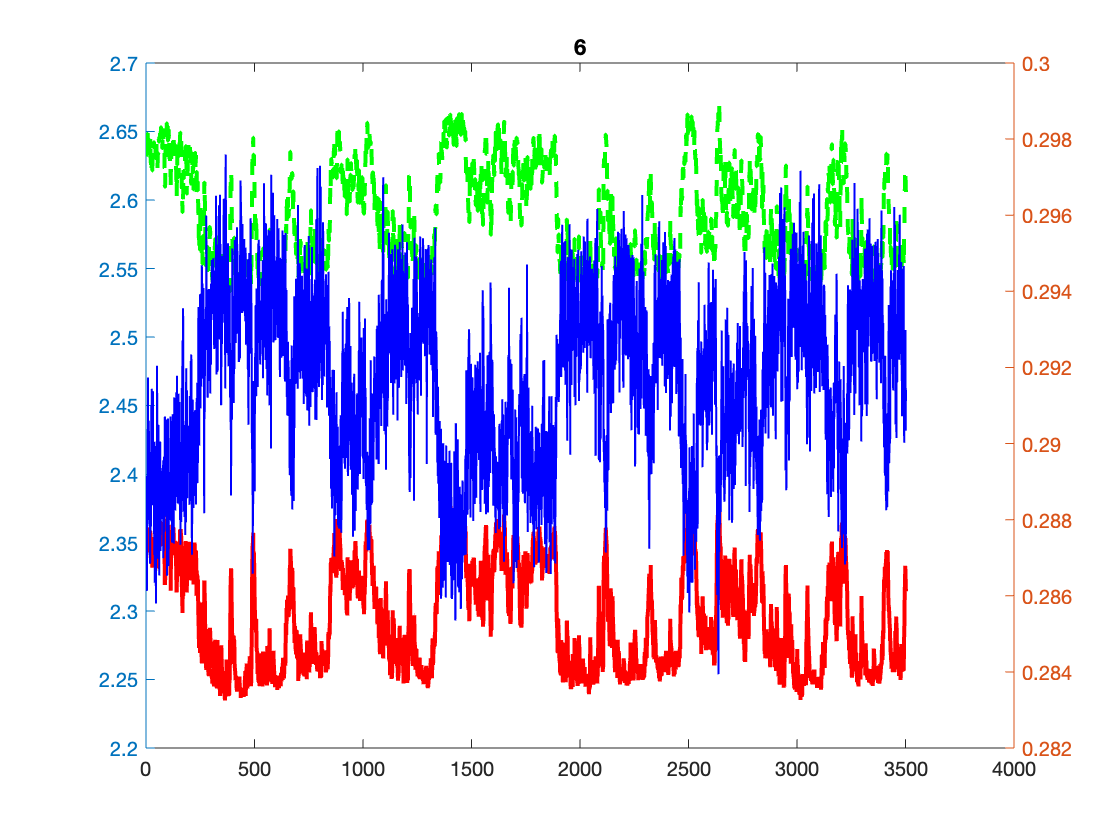

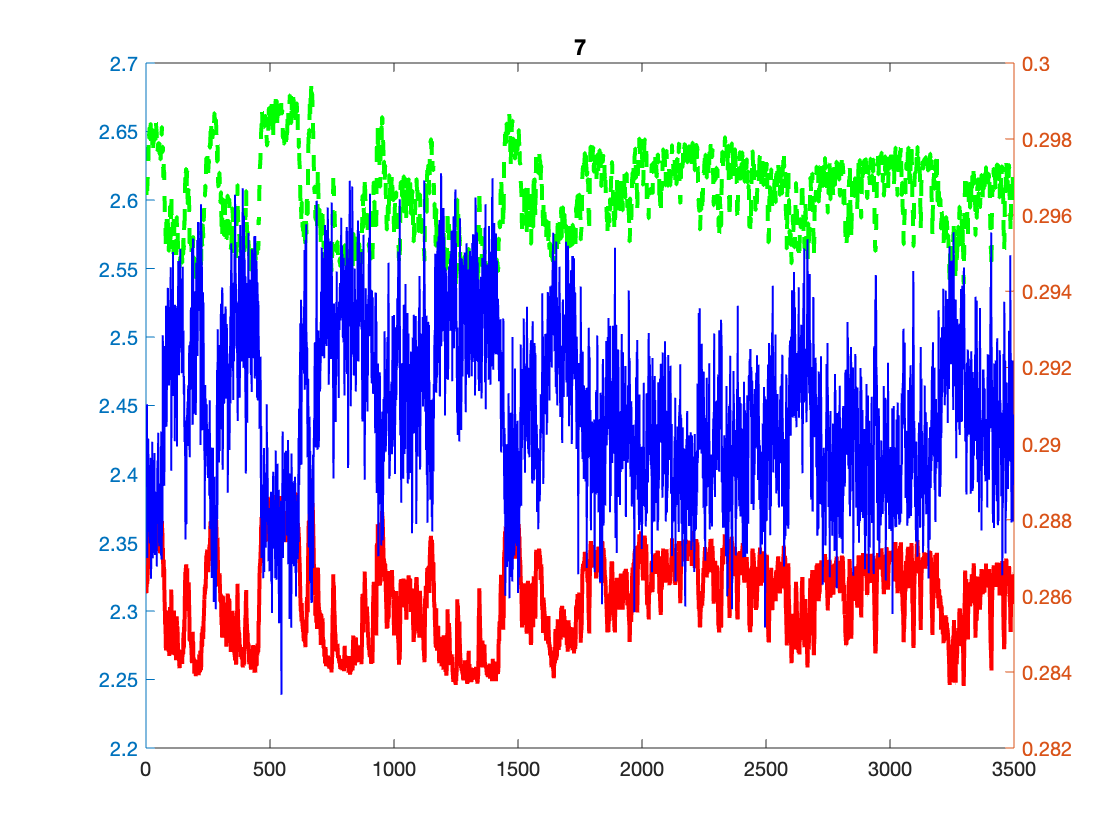

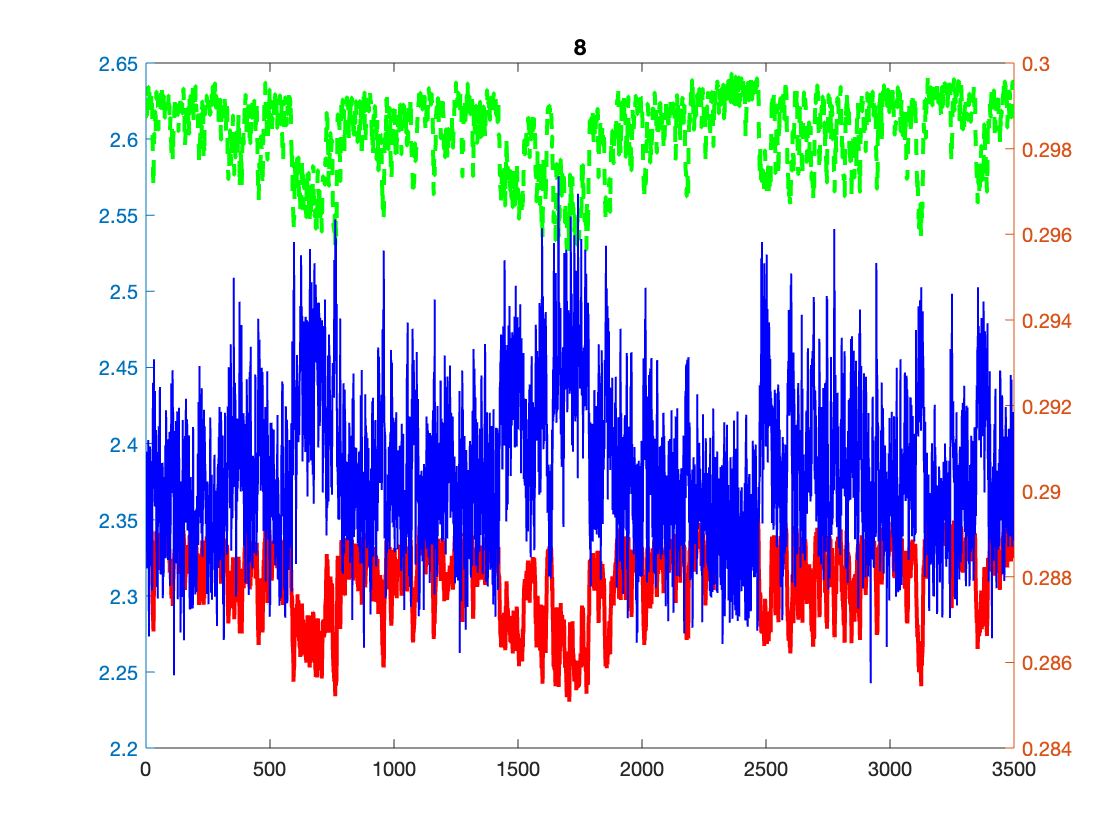


for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220228_fixpeak.mat'];
    load(filename)
    %subplot(6,4,i)
    figure
    yyaxis left
    plot(tau_empTrunc,'Color','Red','LineWidth',2)
    fixed=tau_empTrunc;

    hold on
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220306_NoPrePeak.mat'];
    load(filename)
    flexible=tau_empTrunc;
    plot(tau_empTrunc,'Color','Green','LineWidth',2)
    
    
    difference=flexible-fixed;
    yyaxis right
    plot(difference,'Color','Blue','LineWidth',1)

    title([num2str(i)])

end

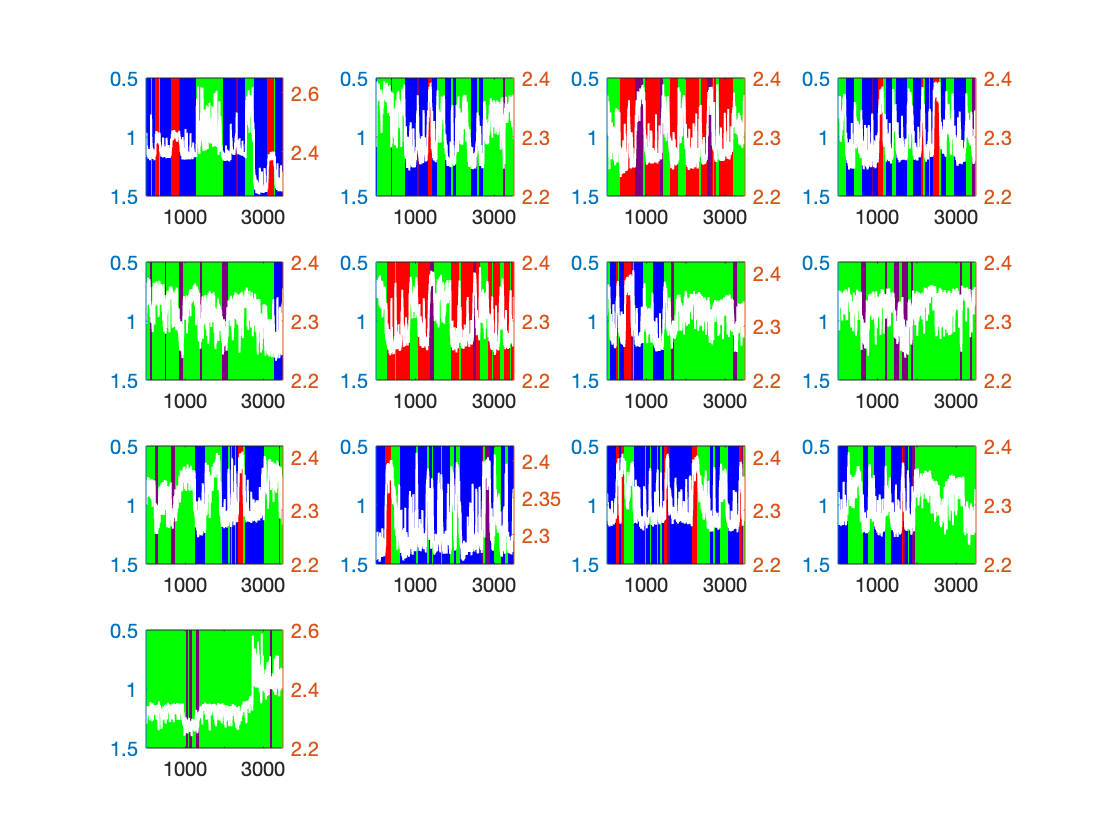

figure
for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220222_peaktest.mat'];
    load(filename)
    eval(['curr_states=states_for_time_',num2str(Dark_hours(i)),';'])
    subplot(ceil(size(Dark_hours,2)/4),4,i)
    yyaxis left
    imagesc(curr_states)
    colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
    
    
    yyaxis right
    plot(tau_empTrunc,'LineWidth',1,'Color','white')
end

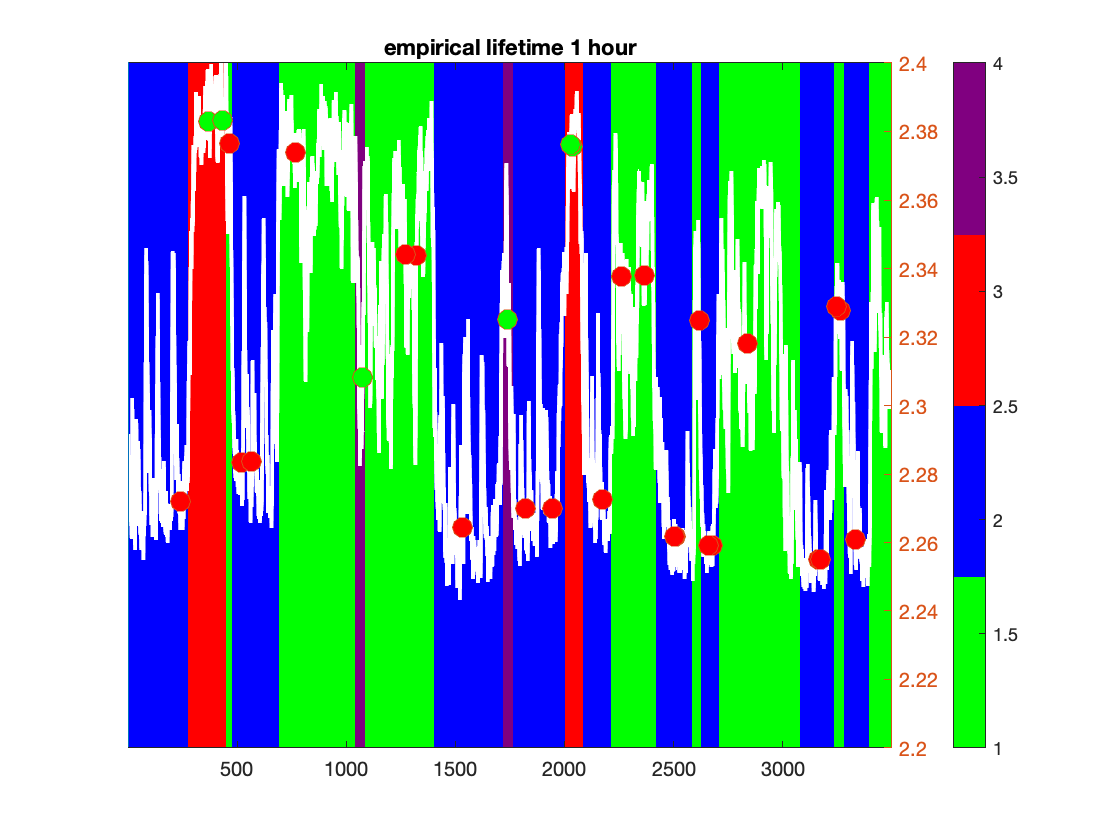

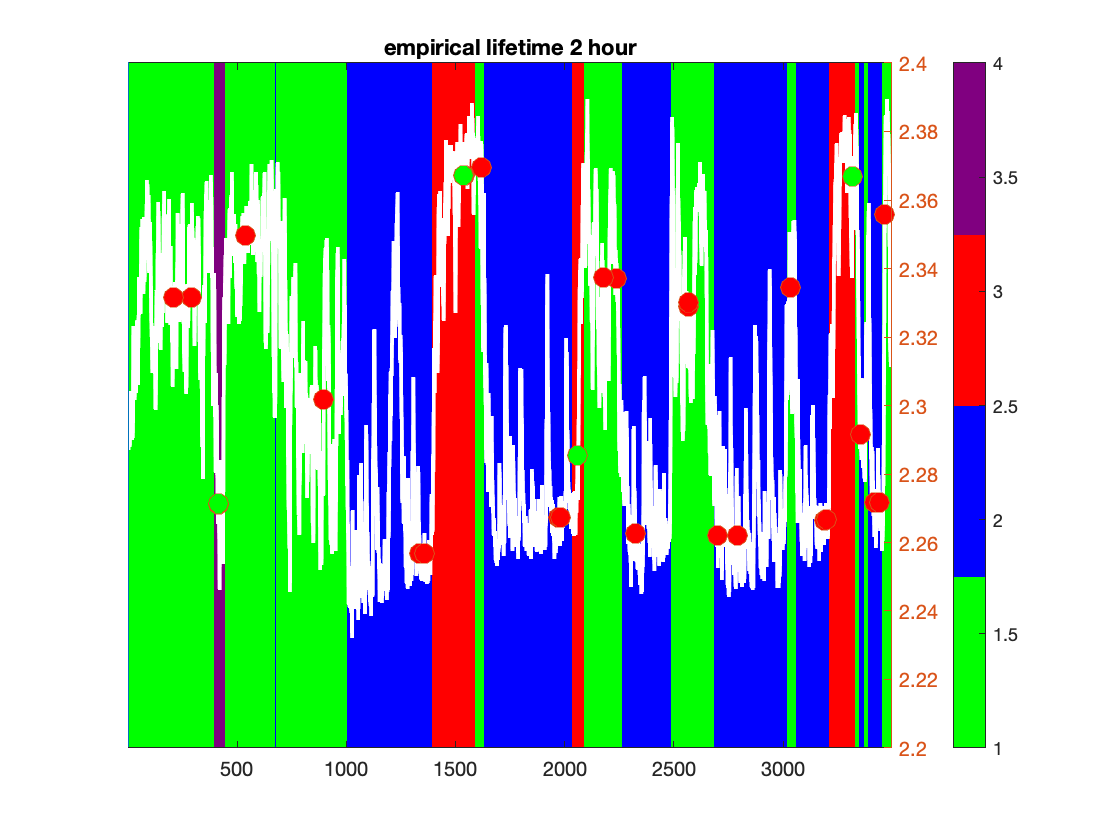

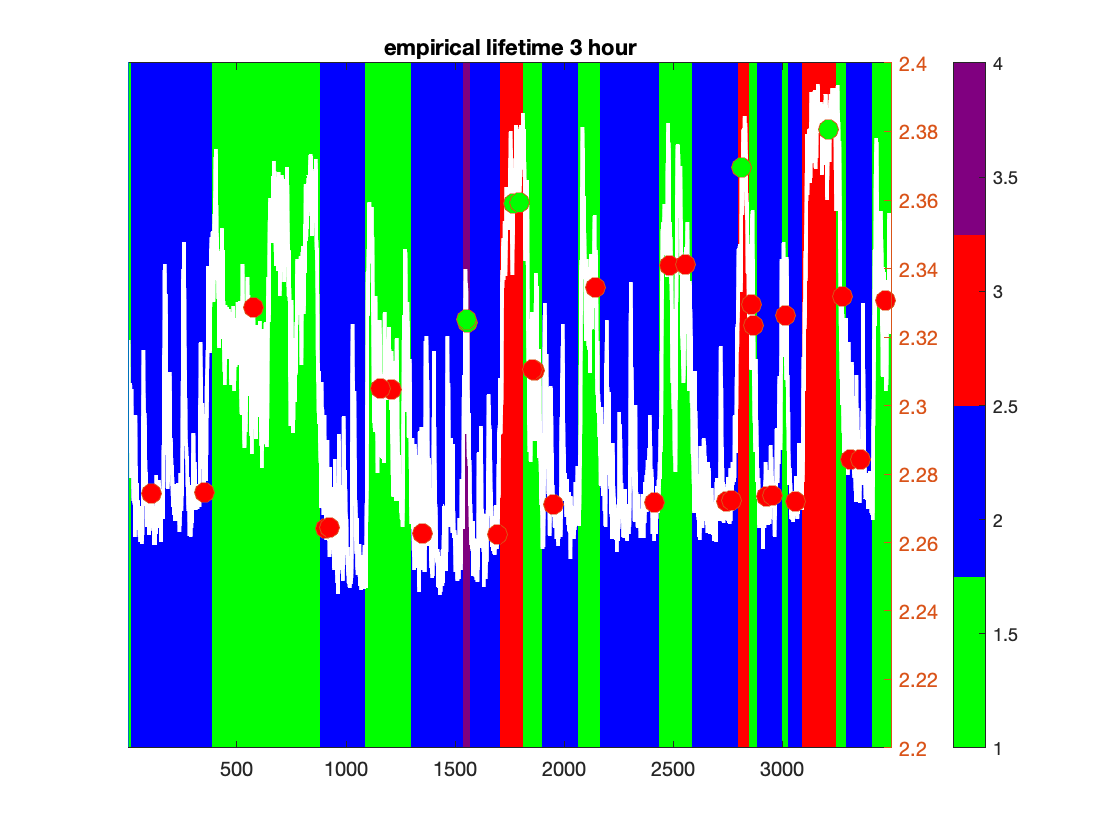

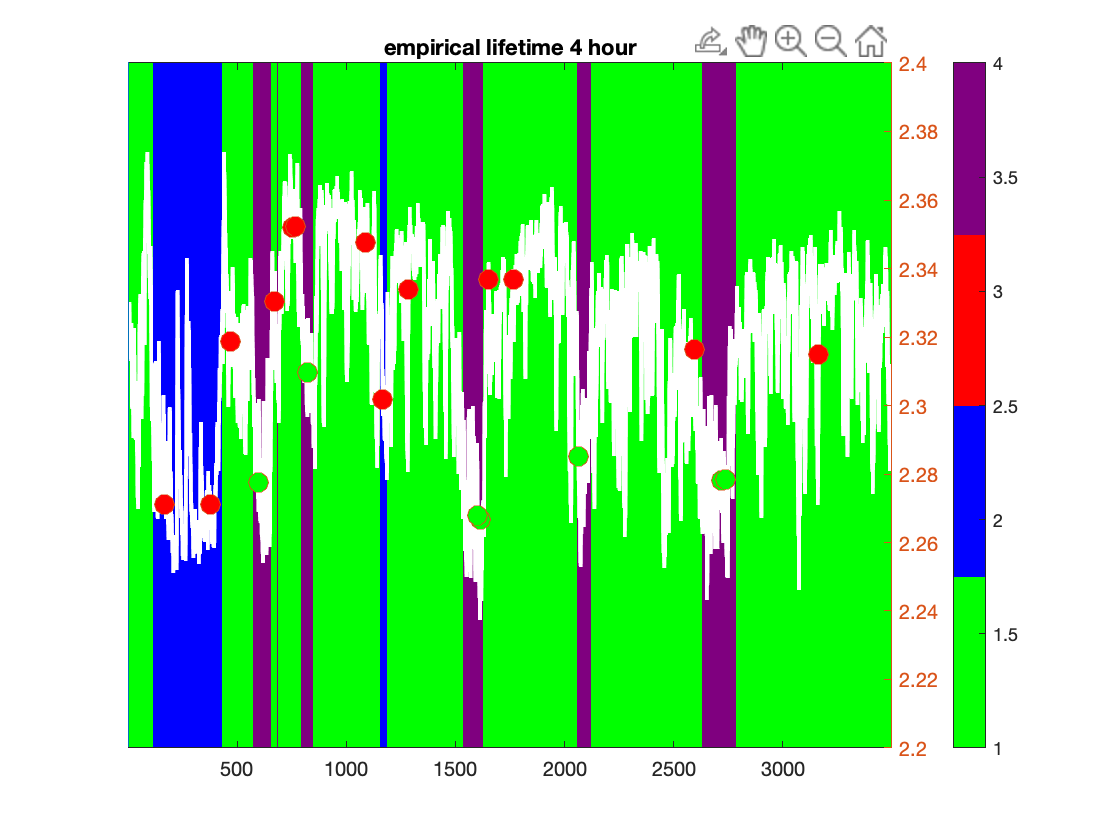

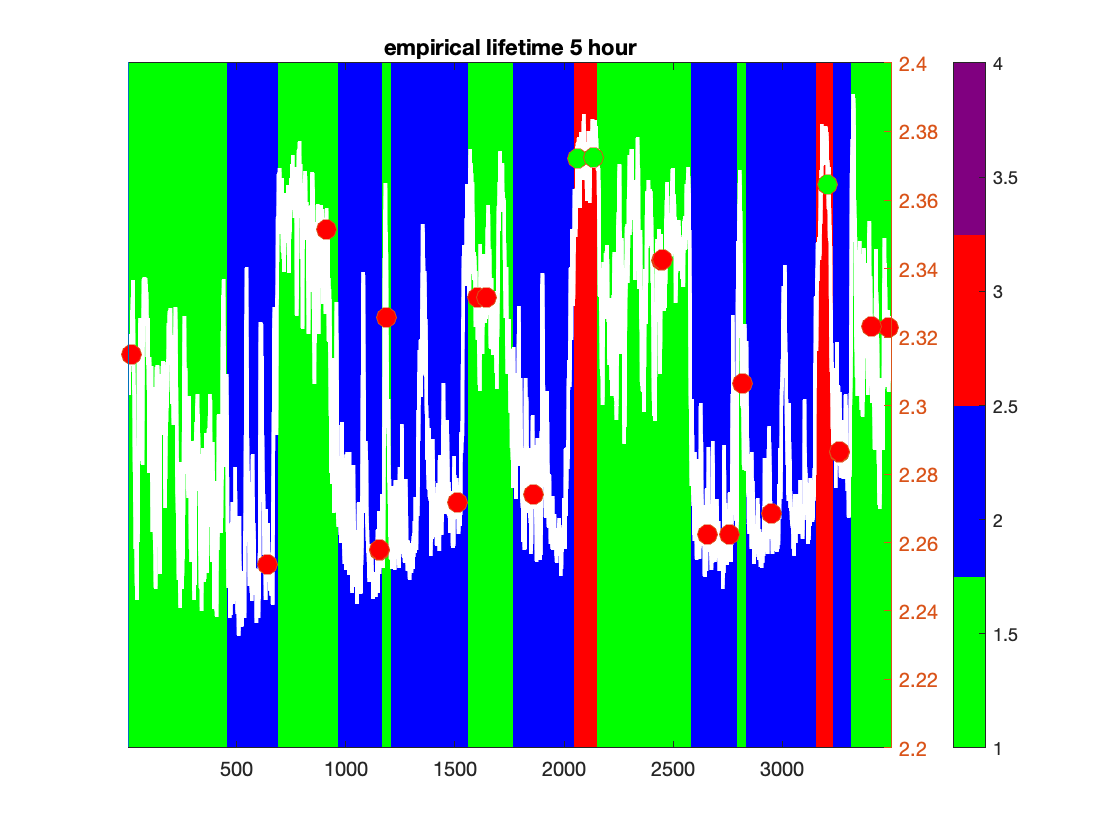

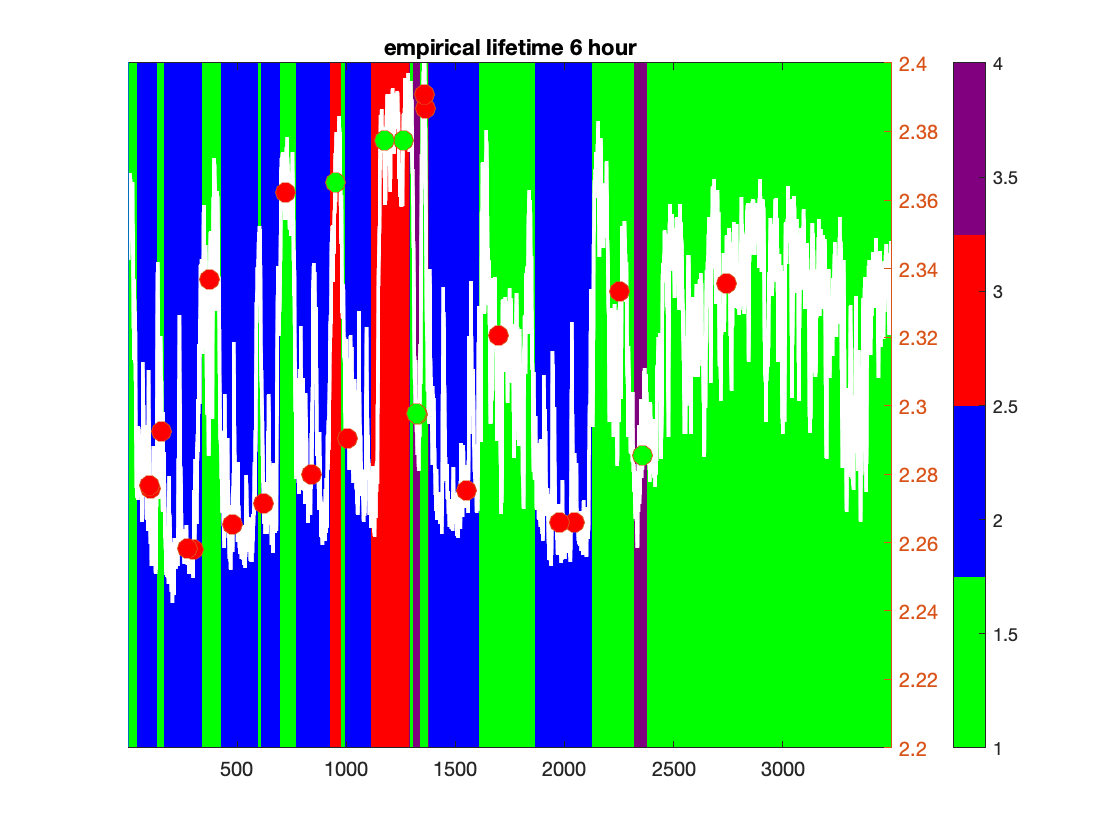

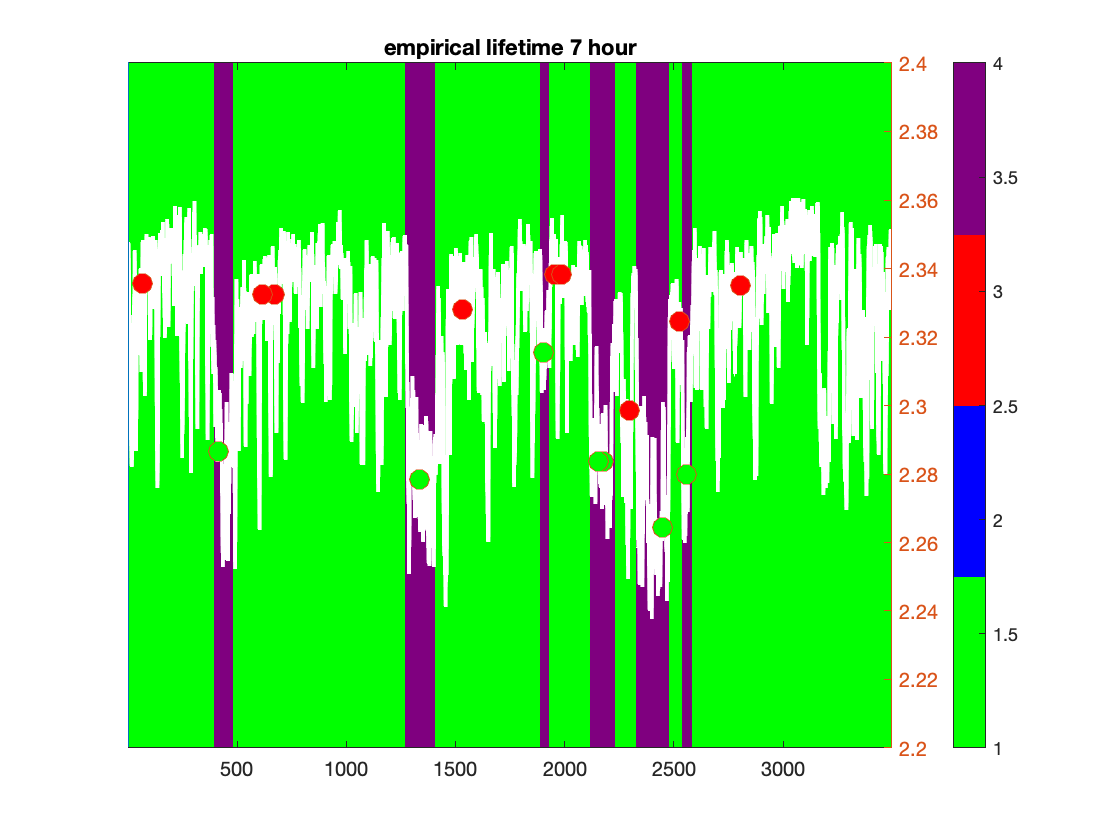

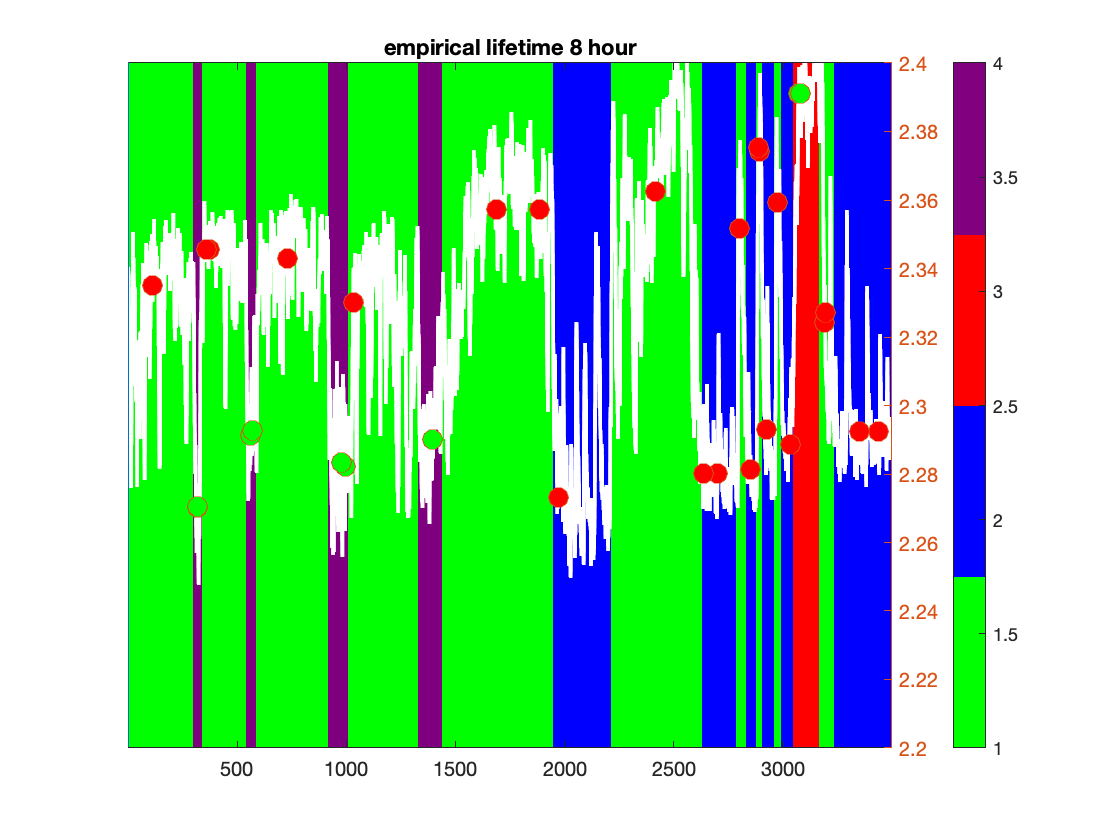

figure

this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 151×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 120×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 20×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 24×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 20×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 63×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 58×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 371×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 297×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 199×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 205×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 213×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 240×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 33×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 138×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 107×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 87×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 166×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 102×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 272×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 153×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 211×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 52×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 35×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 120×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 24×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 67×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 158×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 44×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 124×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 204×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 317×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 143×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 82×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 28×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 3×1
     1
     2
     3


this_median_time = 107×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 56×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 311×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 28×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 350×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 95×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 429×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 64×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 514×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 152×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 1170×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 232×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 278×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 201×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 358×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 205×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 283×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 102×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 433×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 216×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 321×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 82×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 81×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 228×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 93×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 32×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 174×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 86×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 174×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 12×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 83×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 7×1
     1
     2
     3
     4
     5
     6
     7


this_median_time = 76×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 154×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 52×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 20×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 119×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 177×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 5×1
     1
     2
     3
     4
     5


this_median_time = 13×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 36×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 37×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 4×1
     1
     2
     3
     4


this_median_time = 229×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 260×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 263×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 193×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 60×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 1513×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 86×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 213×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 576×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 142×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 479×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 189×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 119×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 95×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 154×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 60×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 48×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 1206×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 43×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 205×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 43×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 113×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 223×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 91×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 323×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 106×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 511×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 268×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 416×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 159×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 44×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 47×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 28×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 58×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 32×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 55×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 124×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 66×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 490×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 366×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 39×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 71×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 239×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 146×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 224×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 248×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 13×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 146×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 44×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 236×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 52×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 88×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 20×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 213×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 24×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 197×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 103×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 5×1
     1
     2
     3
     4
     5


this_median_time = 44×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 97×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 562×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 36×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 36×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 147×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 89×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 178×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 120×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 59×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 159×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 227×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 71×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 21×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 83×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 245×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 48×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 16×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 44×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 13×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 154×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 45×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 12×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 36×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 33×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 154×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 48×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 36×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 71×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 76×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 60×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 564×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 140×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 317×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 93×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 39×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 120×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 217×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 274×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 66×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 20×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 24×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 48×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 254×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 374×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 146×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 150×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 263×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 154×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 283×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 41×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 40×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 67×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 37×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 83×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 75×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 1539×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 5×1
     1
     2
     3
     4
     5


this_median_time = 3×1
     1
     2
     3


this_median_time = 1009×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 64×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 28×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 72×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 103×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 71×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 1824×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 43×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


this_median_time = 290×1
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10


for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220222_peaktest.mat'];
    load(filename)
    eval(['curr_states=states_for_time_',num2str(Dark_hours(i)),';'])
    transition_time=[1];
    for j=1:(size(curr_states,2)-1)
        if curr_states(j+1)~=curr_states(j)
            transition_time=[transition_time j];
        end
    end
    transition_time=[transition_time size(curr_states,2)];
    median_time=[];
    for k=1:(size(transition_time,2)-1)
        this_median_time=find(tau_empTrunc(transition_time(k):transition_time(k+1)));
    end
    figure
    yyaxis left
    imagesc(curr_states)
    colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
    
    
    yyaxis right
    plot(tau_empTrunc,'LineWidth',1,'Color','white')
end


analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '122221_1521_1_005FLIM001.mat'
     folder: '/Volumes/PcSSDA/2021Fall_FLP/122221_1521_1_005'
       date: '22-Dec-2021 16:05:32'
      bytes: 3116
      isdir: 0
    datenum: 7.3851e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all=[];
tau_avg_all=[];
tau_empTrunc_all_DC=[];
tau_avg_all_DC=[];
tau_empTrunc_all_AC=[];
tau_avg_all_AC=[];
intensity_all=[];
intensity_all_DC=[];
intensity_all_AC=[];
time_z_all=[];
states_all=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h_20220228_flexiblepeak.mat'];
    load(filename);

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));

    filename_plus=[analysis_name,num2str(i),'h_20220228_flexiblepeak_plus.mat'];
    save(filename_plus,'tau_empTrunc_DC','tau_empTrunc_AC','tau_avg_DC', 'tau_avg_AC', 'intensity_DC','intensity_AC','time_z','time');

    tau_empTrunc_all=[tau_empTrunc_all; tau_empTrunc];
    tau_avg_all=[tau_avg_all; tau_avg];
    tau_empTrunc_all_DC=[tau_empTrunc_all_DC; tau_empTrunc_DC];
    tau_avg_all_DC=[tau_avg_all_DC; tau_avg_DC];
    tau_empTrunc_all_AC=[tau_empTrunc_all_AC; tau_empTrunc_AC];
    tau_avg_all_AC=[tau_avg_all_AC; tau_avg_AC];
    intensity_all=[intensity_all; photoncount];
    intensity_all_DC=[intensity_all_DC; intensity_DC];
    intensity_all_AC=[intensity_all_AC; intensity_AC];
    time_z_all=[time_z_all; time_z];

end

for i=1:size(time_z_all,1)
    if time_z_all(i)>86400
        time_z_all(i)=time_z_all(i)-86400;
    end
end

save('FLiP_analysis_all_20220222_peaktest.mat','tau_empTrunc_all','tau_avg_all', 'tau_empTrunc_all_DC', 'tau_avg_all_DC',...
    'tau_empTrunc_all_AC','tau_avg_all_AC','intensity_all', 'intensity_all_DC', 'intensity_all_AC', 'time_z_all');



tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220228_flexiblepeak.mat'];
    load(filename);

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end


if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_DC_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_DC_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);



% This is the 1st format, a 900 long number serie, called states_#h.
for i=1:size(Dark_hours,2) % Depending on how many acquistions we have from sleep scoring
    
    states=readNPY(['StatesAcq',num2str(Dark_hours(i)),'_hr0.npy']);
    eval(['states_',num2str(Dark_hours(i)),'h=states;']);
end

% This is the 2nd format, a 3600 long number serie, called
% states_in_seconds_#.
for i=1:size(Dark_hours,2)
    eval(['states_in_seconds_',num2str(Dark_hours(i)),'=[];']);
    for j=1:900
        eval(['states_in_seconds_',num2str(Dark_hours(i)),'((4*j-3):4*j)=states_',num2str(Dark_hours(i)),'h(j);']);
    end
end


states_for_time_all=[];
for i=1:size(Dark_hours,2)

    filename_plus=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_plus.mat'];
    load(filename_plus);

    eval(['this_hour=states_in_seconds_',num2str(Dark_hours(i)),';'])
    states_for_time=[];
    

    for j=1:length(time)
    if ceil(time(j))<3600
       states_for_time(j)=this_hour(ceil(time(j)));
    else
       states_for_time(j)=this_hour(3600);
    end
    end

    eval(['states_for_time_',num2str(Dark_hours(i)),'=states_for_time;'])
    states_for_time_all=[states_for_time_all;states_for_time'];
end

states_for_time_all_dark= states_for_time_all(dark_acqs);


mkdir([analysis_name,'csv_20220228_flexible'])

csv_name=[analysis_name,'csv_20220228_flexible/'];

time_csv=[csv_name,'time.csv'];
states_csv=[csv_name,'states.csv'];
lft_emp_csv=[csv_name,'lft_emp.csv'];
lft_emp_DC_csv=[csv_name,'lft_emp_DC.csv'];
lft_emp_AC_csv=[csv_name,'lft_emp_AC.csv'];
lft_fit_csv=[csv_name,'lft_fit.csv'];
lft_fit_DC_csv=[csv_name,'lft_fit_DC.csv'];
lft_fit_AC_csv=[csv_name,'lft_fit_AC.csv'];
intensity_csv=[csv_name,'intensity.csv'];
intensity_DC_csv=[csv_name,'intensity_DC.csv'];
intensity_AC_csv=[csv_name,'intensity_AC.csv'];

csvwrite(time_csv, time_z_all_darkonly)
csvwrite(states_csv, states_for_time_all_dark)
csvwrite(lft_emp_csv, tau_empTrunc_all_darkonly)
csvwrite(lft_emp_DC_csv, tau_empTrunc_all_DC_darkonly)
csvwrite(lft_emp_AC_csv, tau_empTrunc_all_AC_darkonly)
csvwrite(lft_fit_csv, tau_avg_all_darkonly)
csvwrite(lft_fit_DC_csv, tau_avg_all_DC_darkonly)
csvwrite(lft_fit_AC_csv, tau_avg_all_AC_darkonly)
csvwrite(intensity_csv, intensity_all_darkonly)
csvwrite(intensity_DC_csv, intensity_all_DC_darkonly)
csvwrite(intensity_AC_csv, intensity_all_AC_darkonly)



t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];
end

median_time_2=[];
median_2=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
end

median_time_3=[];
median_3=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
end

median_time_4=[];
median_4=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
end


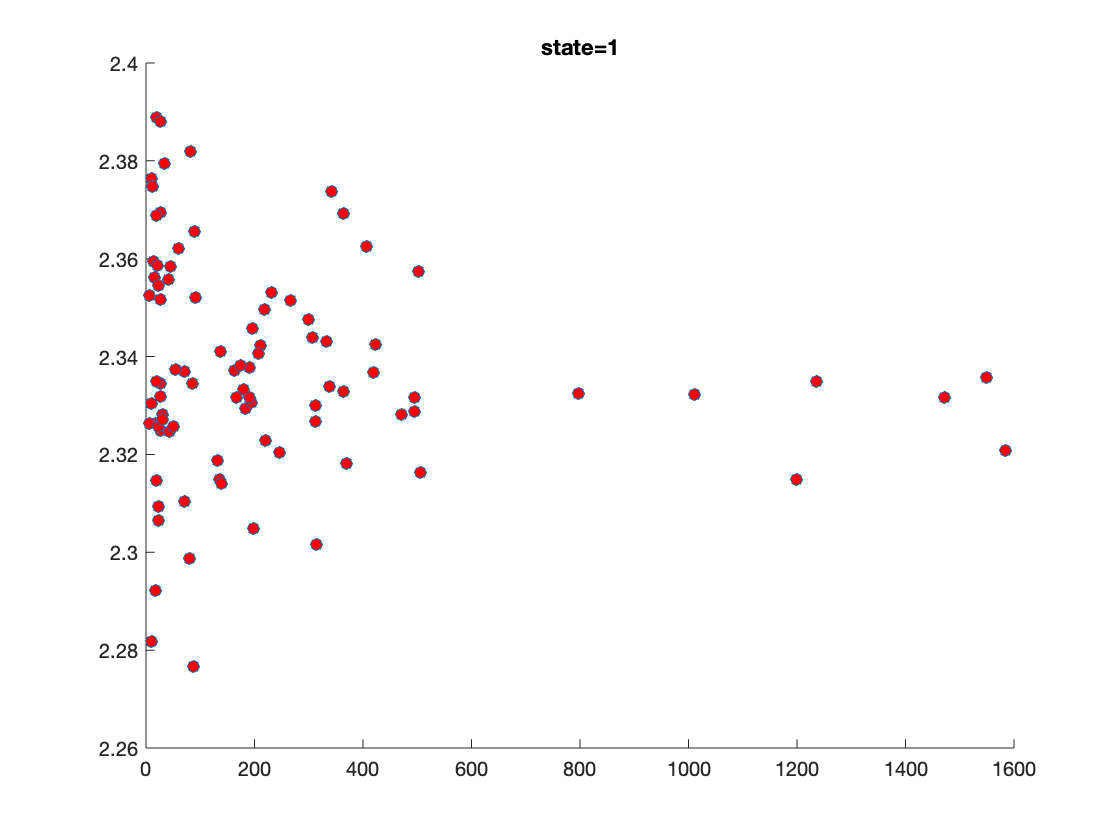

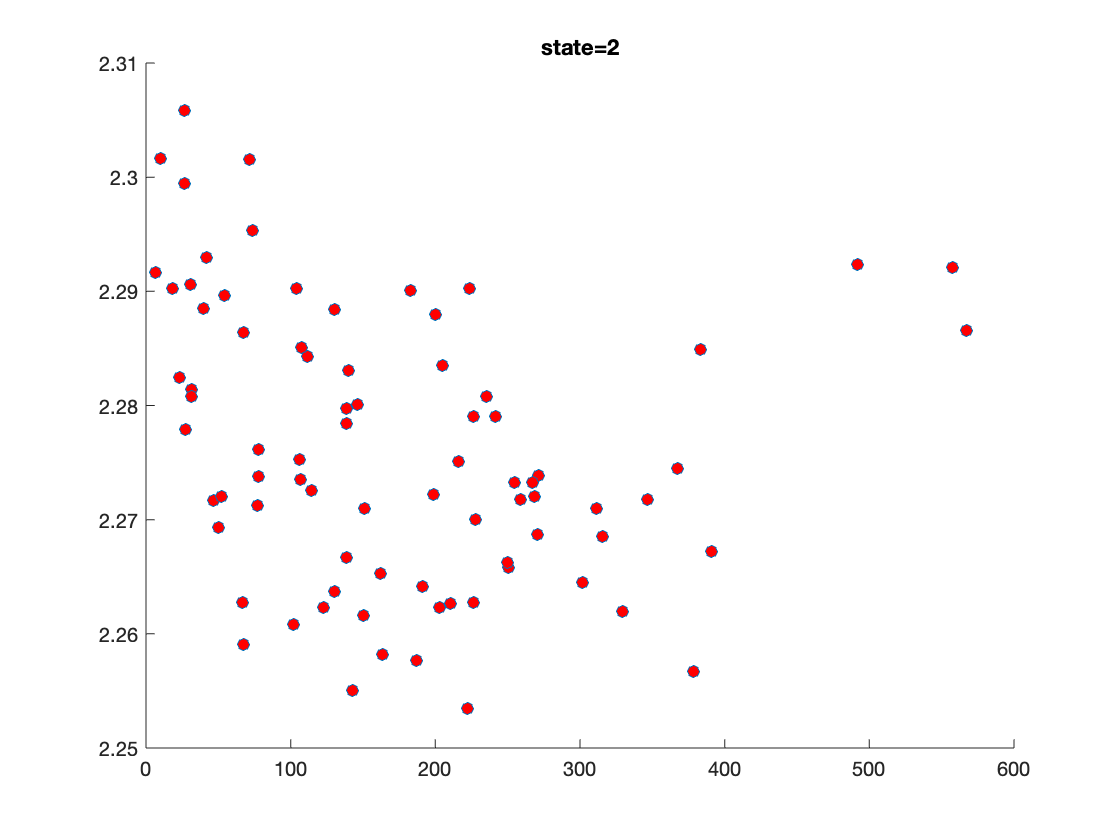

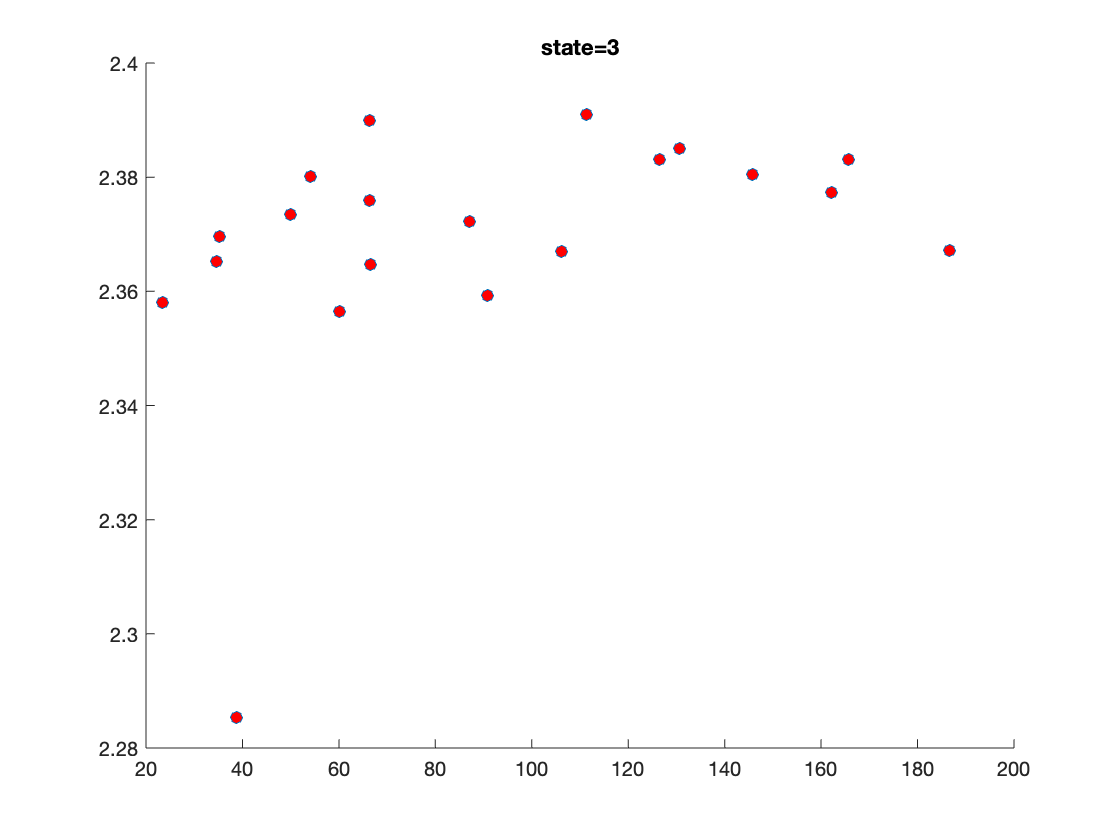

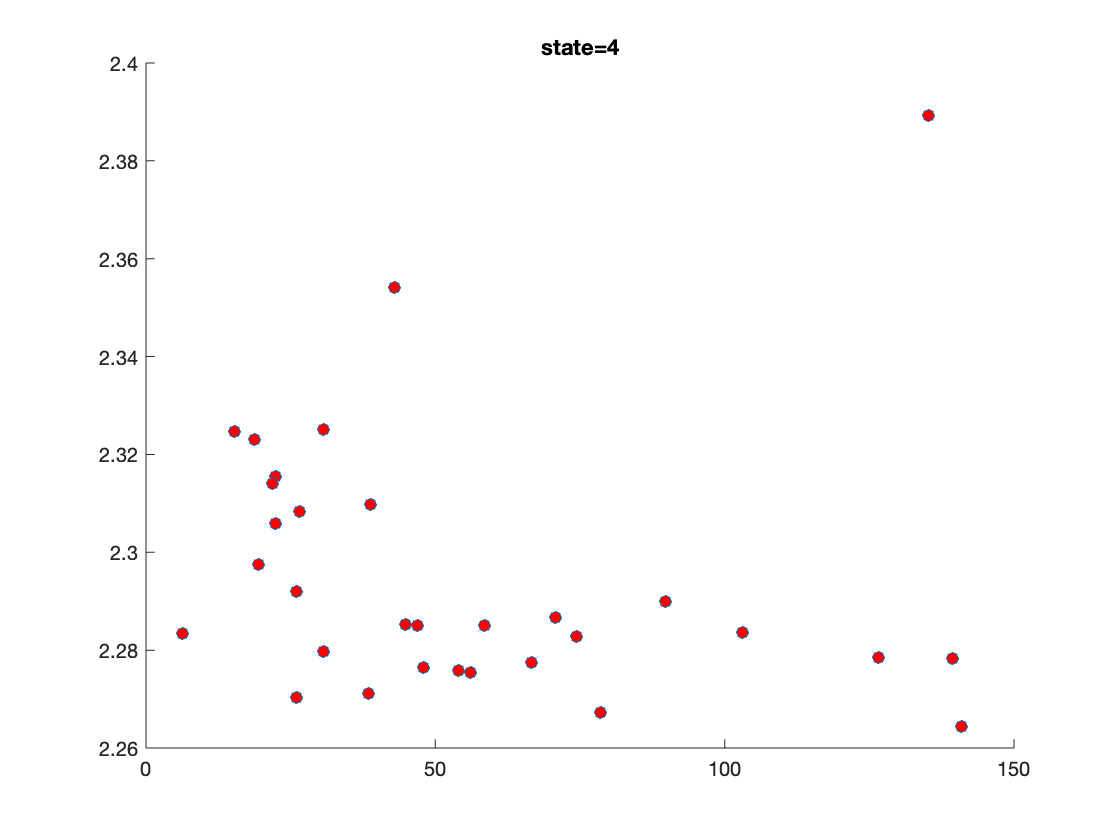

for i=1:4
    eval(['epoch_length=epoch_length_',num2str(i),';'])
    eval(['median_this_state=median_',num2str(i),';'])
    figure
    scatter(epoch_length,median_this_state,'o','MarkerFaceColor','Red')
    title(['state=',num2str(i)])
end

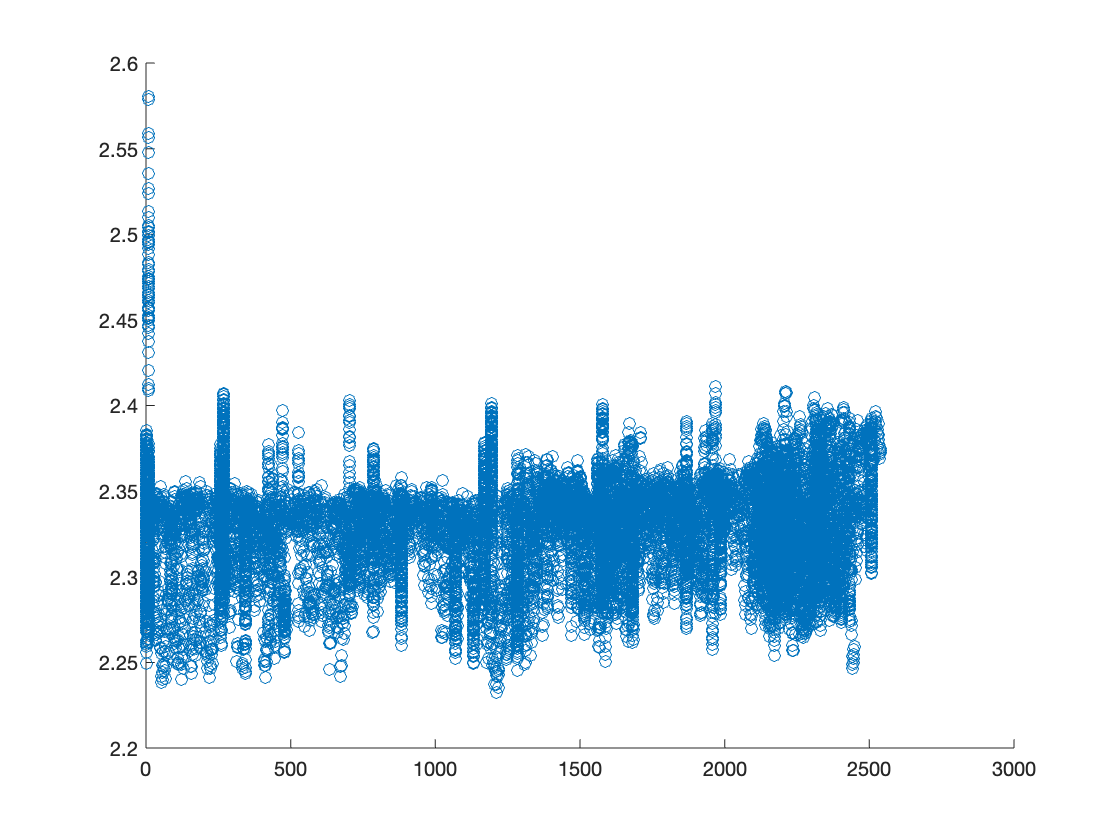

time_before=3600;
lft_with_sleep=[];
sleep_time_for_lft=[];
for i=1:size(t)
    if t(i)>time_before & states_for_time_all_dark(i)==1
        lft_with_sleep=[lft_with_sleep tau_empTrunc_all_darkonly(i)];
        states_before=states_for_time_all_dark(find(t>t(i)-time_before & t<t(i)));
        sleep_time=length(find(states_before==2))+length(find(states_before==3));
        sleep_time_for_lft=[sleep_time_for_lft sleep_time];
    end
end

figure
scatter(sleep_time_for_lft,lft_with_sleep)

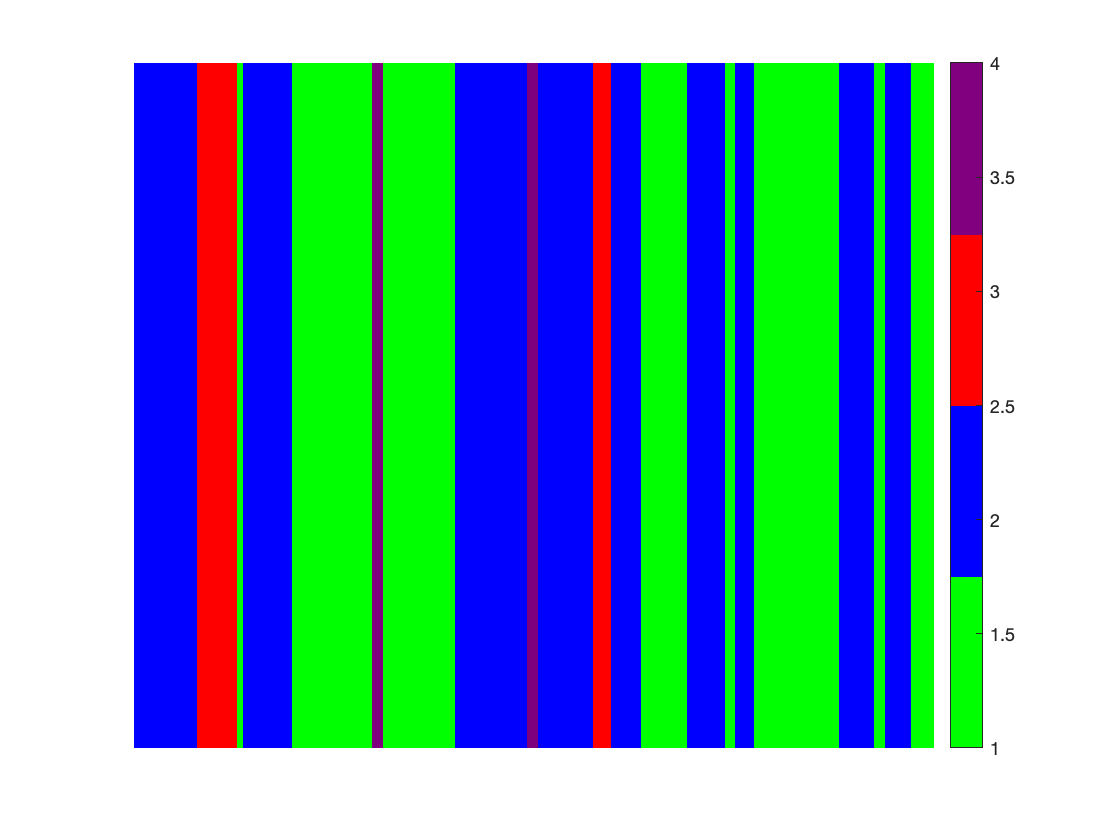

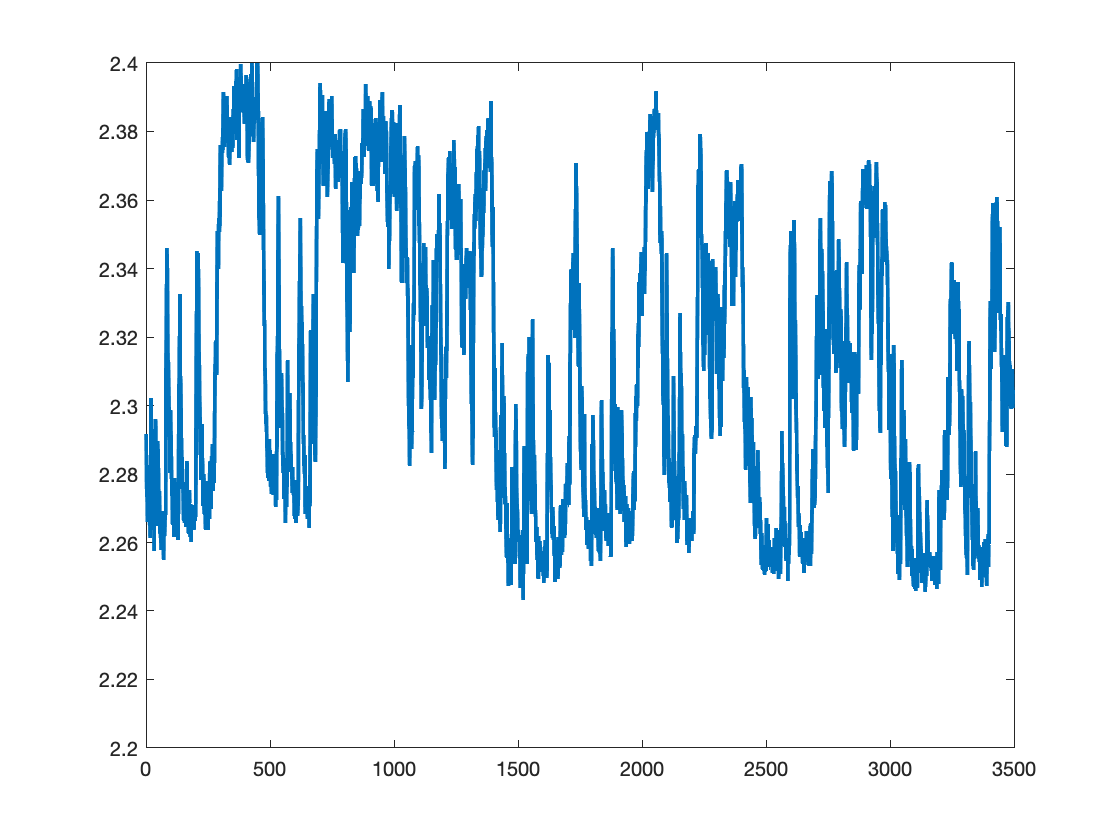

t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

for i=1
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    
    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));
    
    figure
    
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar
    set(gca, 'YTick', []);
%     title(['empirical lifetime ',num2str(i),' hour' ])
    axis off
    
    figure
    
    plot(time_z_all_darkonly(this_plot_points),tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2)
    ylim([2.2 2.4])
    
%     hold on
%     yyaxis right
%     plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
%     plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
%     plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
%     plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')
%     hold off
    
    
    
    
    
    
end

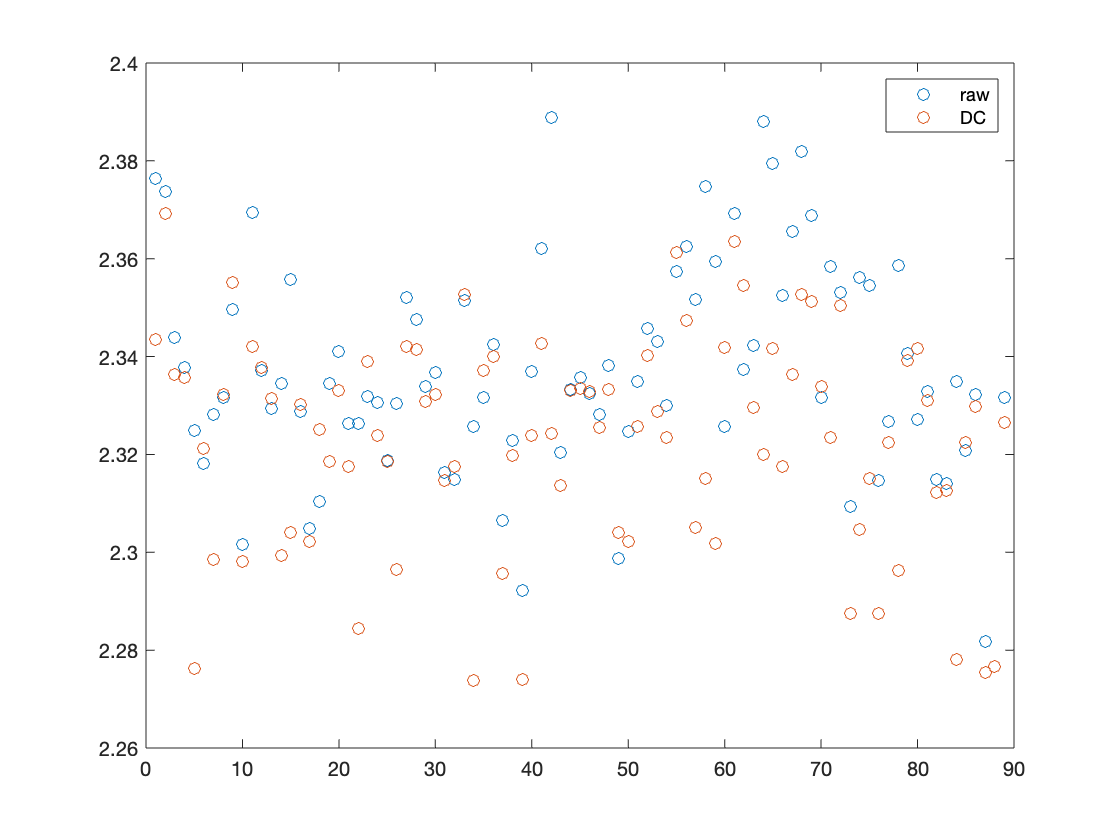

figure
plot(median_1,'o')
hold on
plot(median_1_DC,'o')
legend('raw','DC')

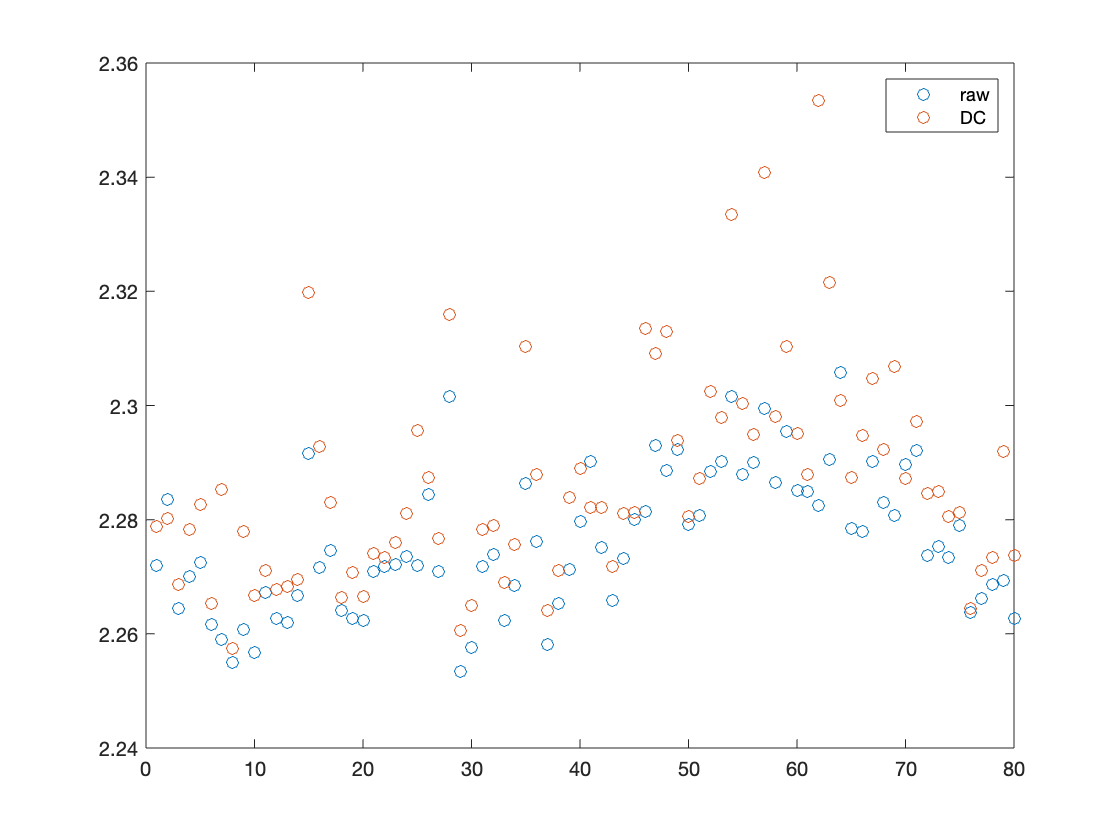

figure
plot(median_2,'o')
hold on
plot(median_2_DC,'o')
legend('raw','DC')

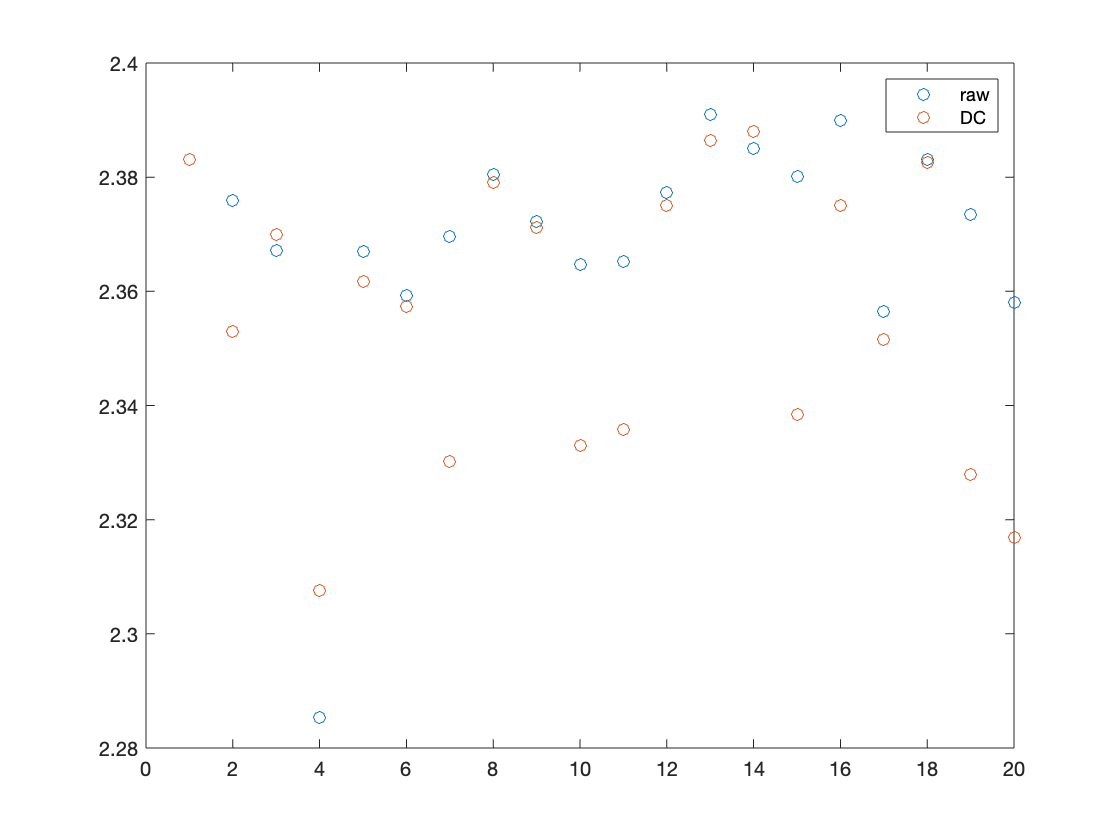

figure
plot(median_3,'o')
hold on
plot(median_3_DC,'o')
legend('raw','DC')

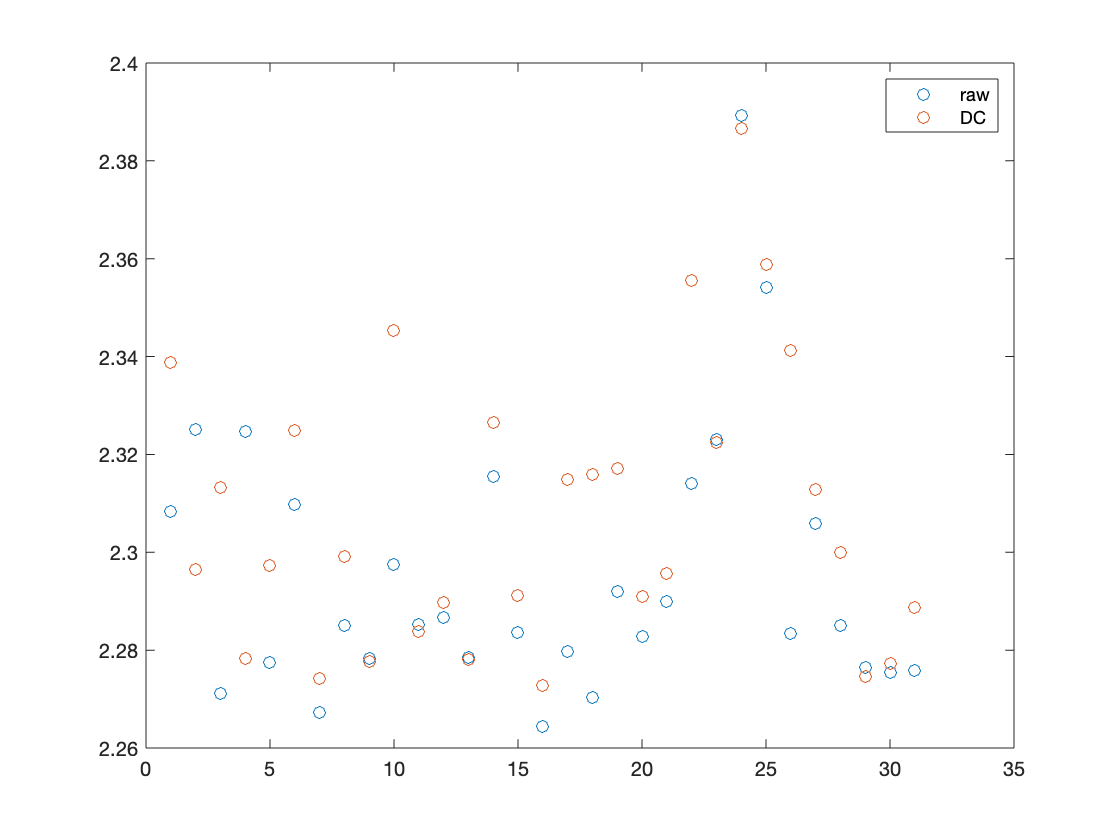

figure
plot(median_4,'o')
hold on
plot(median_4_DC,'o')
legend('raw','DC')

state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1_DC=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_DC_darkonly(state1epochs(i,1):state1epochs(i,2));
    median_1_DC=[median_1_DC median(this_epoch)];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];
end

median_time_2=[];
median_2_DC=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_DC_darkonly(state2epochs(i,1):state2epochs(i,2));
    median_2_DC=[median_2_DC median(this_epoch)];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
end

median_time_3=[];
median_3_DC=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_DC_darkonly(state3epochs(i,1):state3epochs(i,2));
    median_3_DC=[median_3_DC median(this_epoch)];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
end

median_time_4=[];
median_4_DC=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_DC_darkonly(state4epochs(i,1):state4epochs(i,2));
    median_4_DC=[median_4_DC median(this_epoch)];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
end


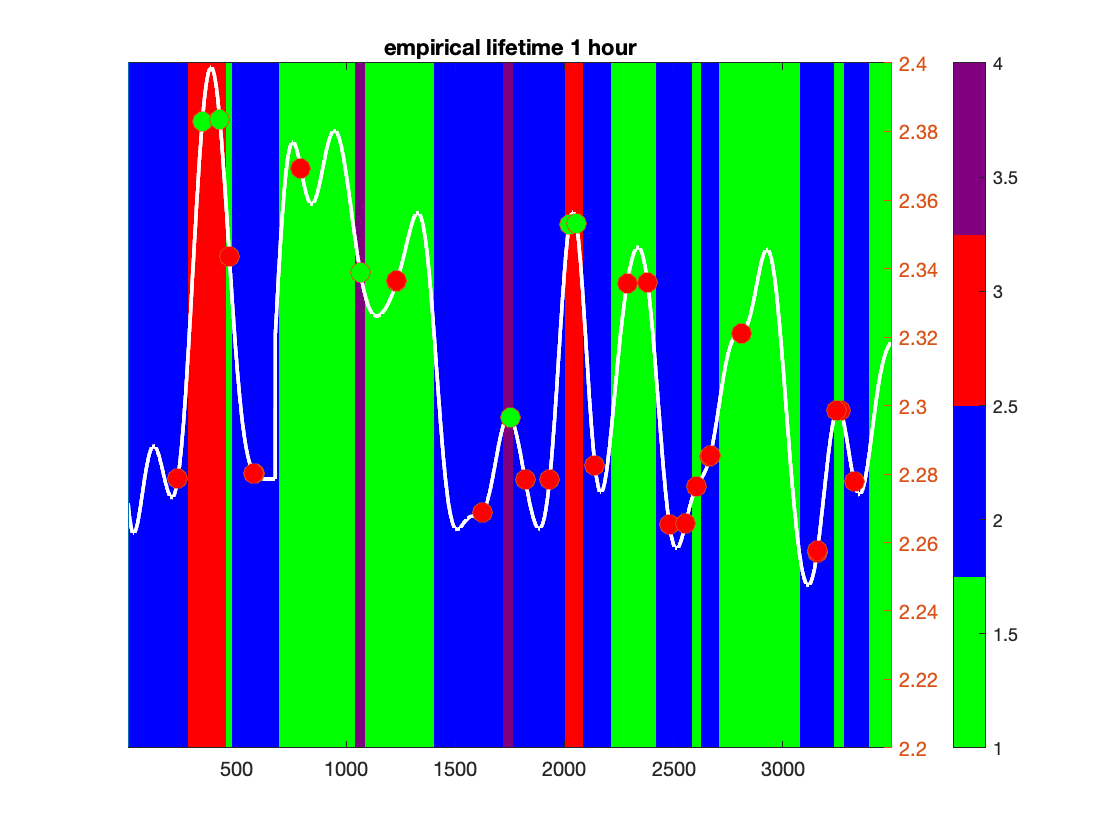

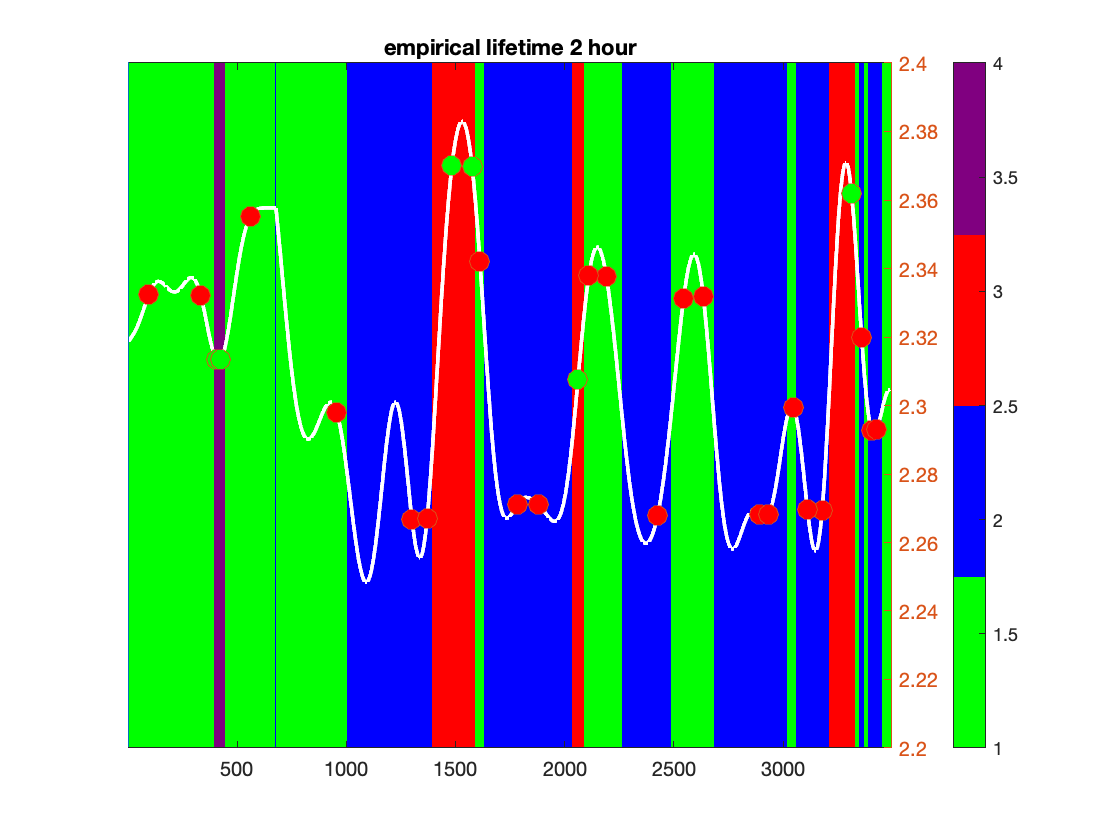

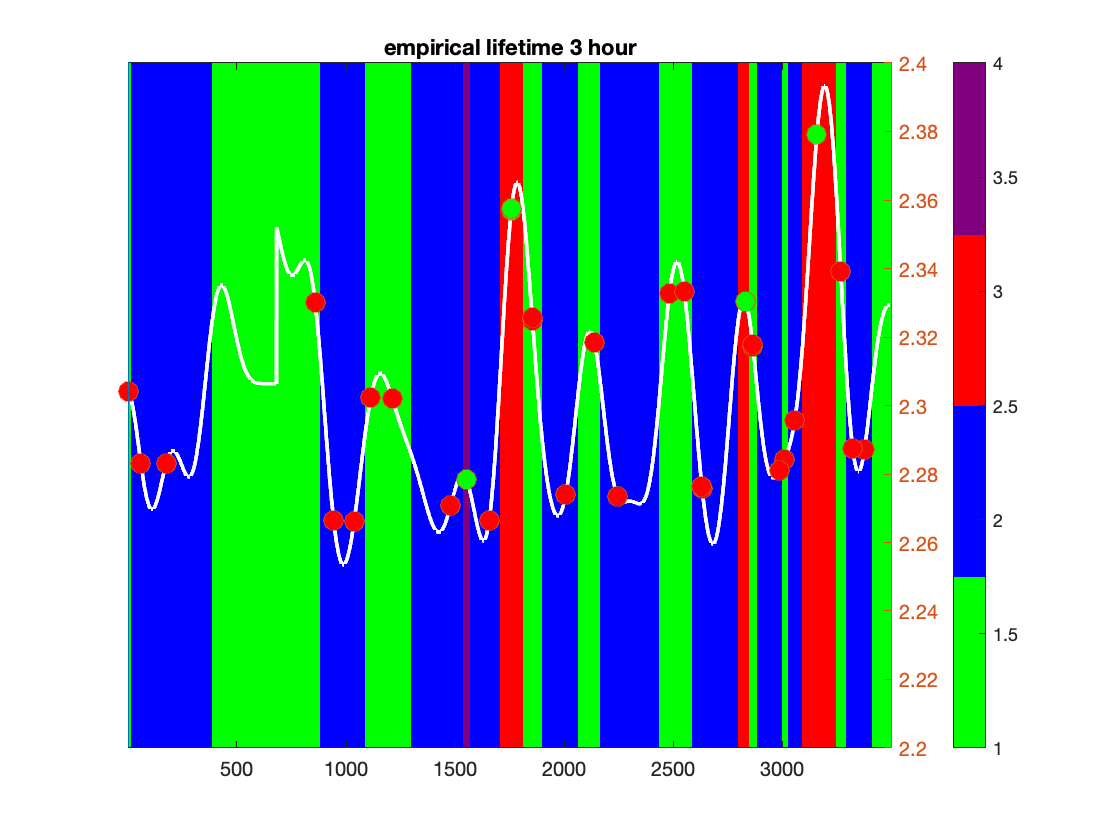

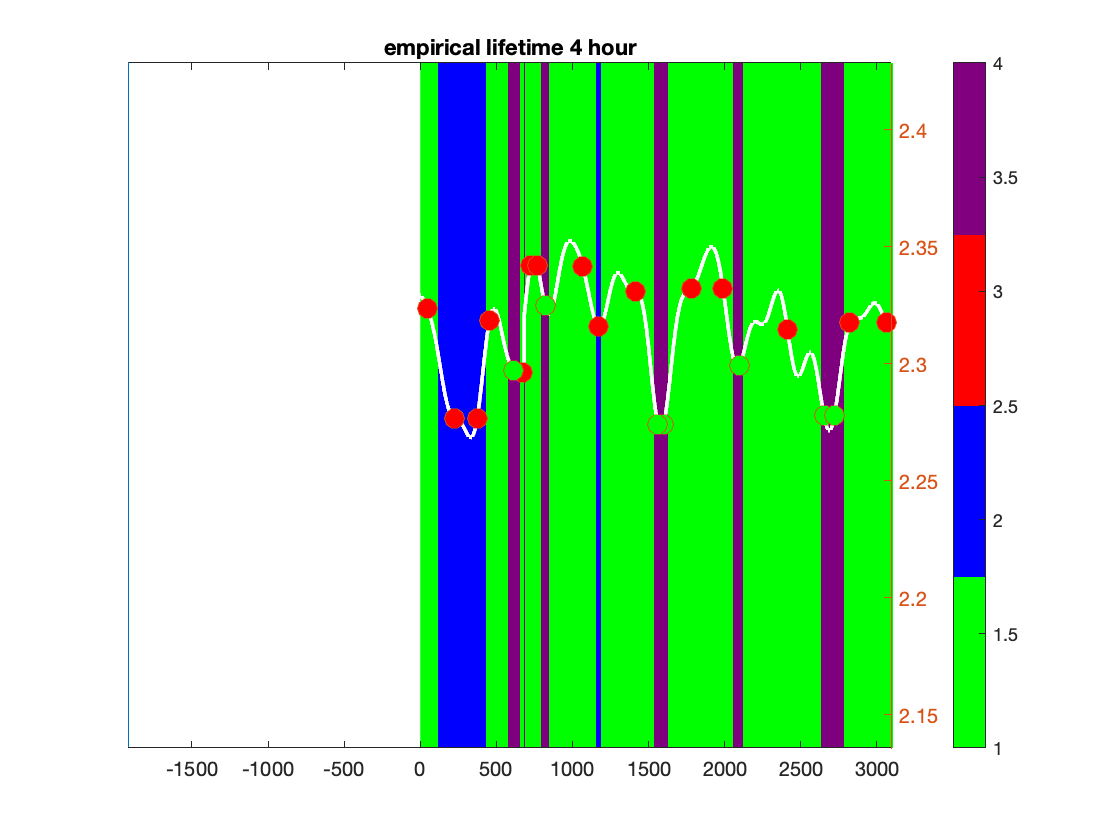

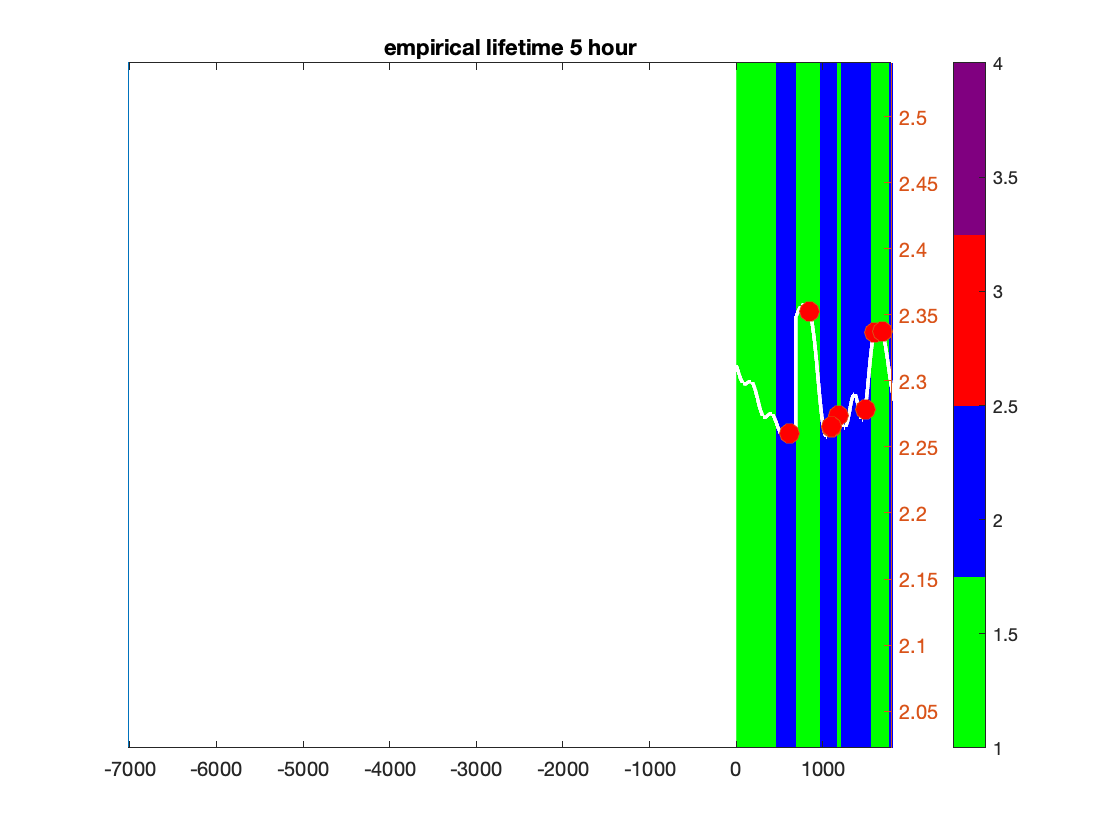

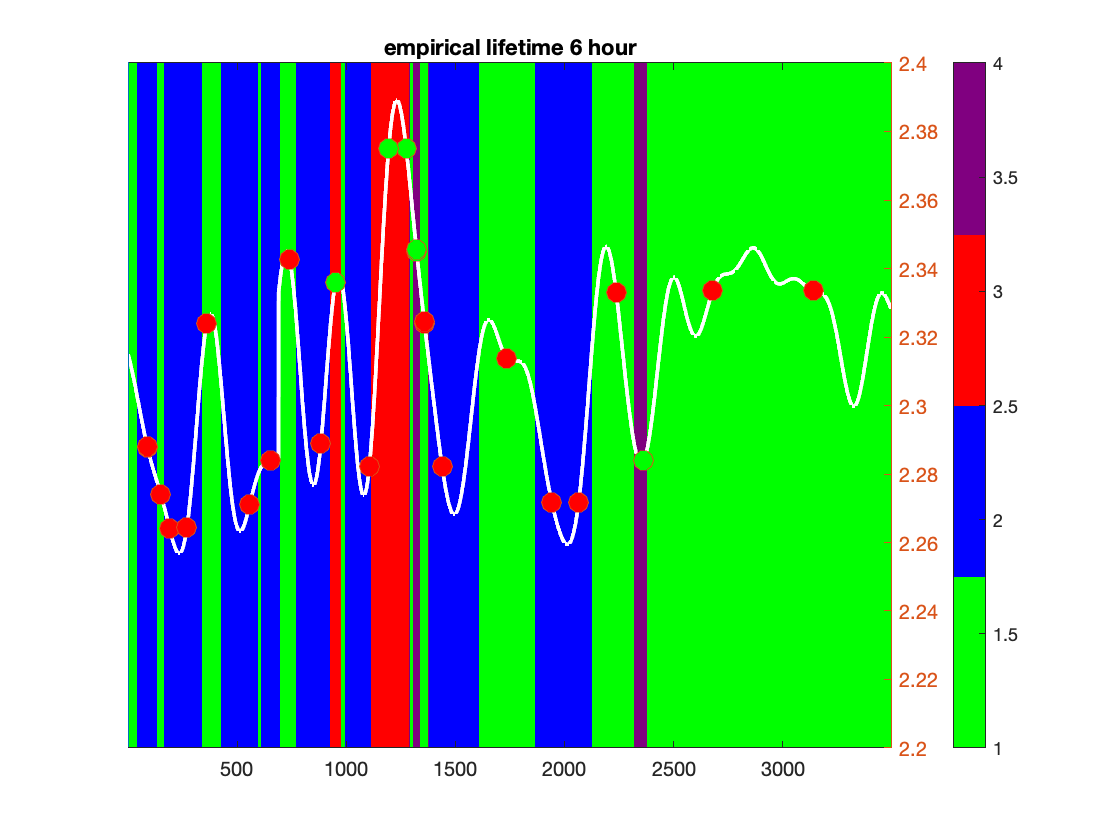

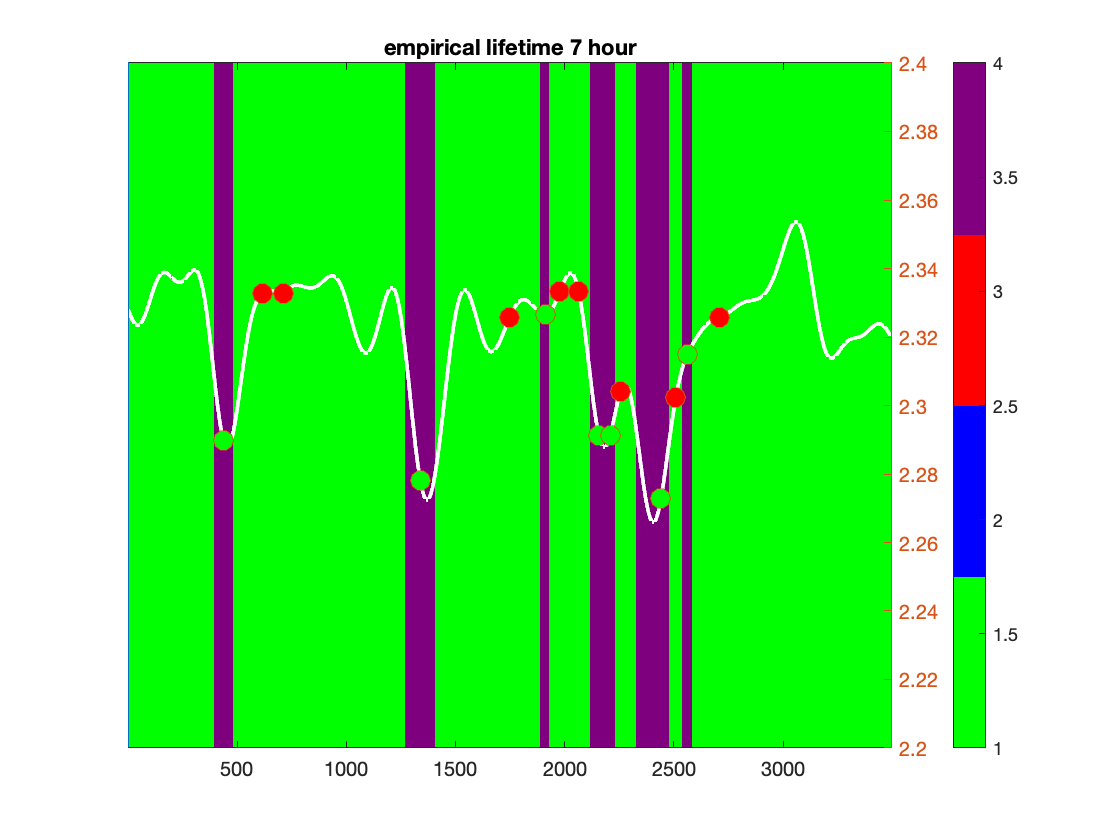

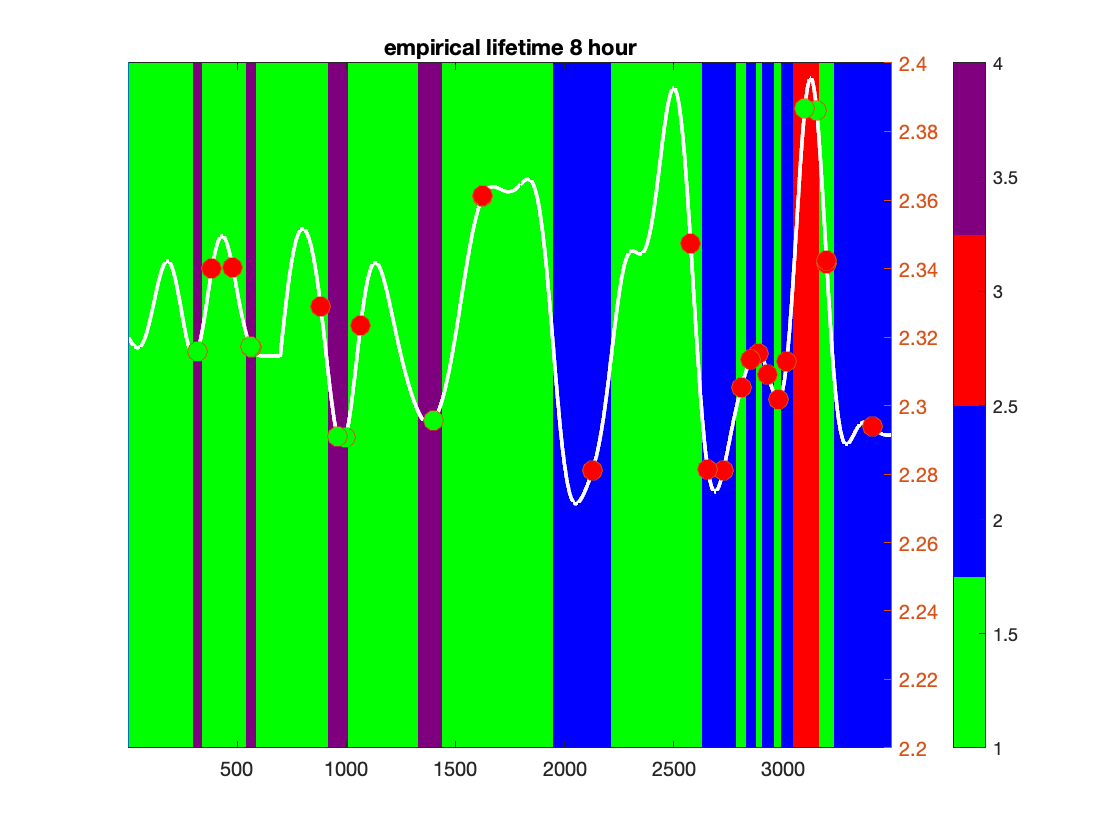

t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    
    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));
    
    figure
    yyaxis left
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar
    set(gca, 'YTick', []);
    title(['empirical lifetime ',num2str(i),' hour' ])
    
    yyaxis right
    plot(tau_empTrunc_all_DC_darkonly(this_plot_points),'LineWidth',2,'Color','white')
    ylim([2.2 2.4])
    
    hold on
    yyaxis right
    plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_DC_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_DC_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_DC_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
    plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_DC_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')
    hold off
    
    
    
    
    
    
end

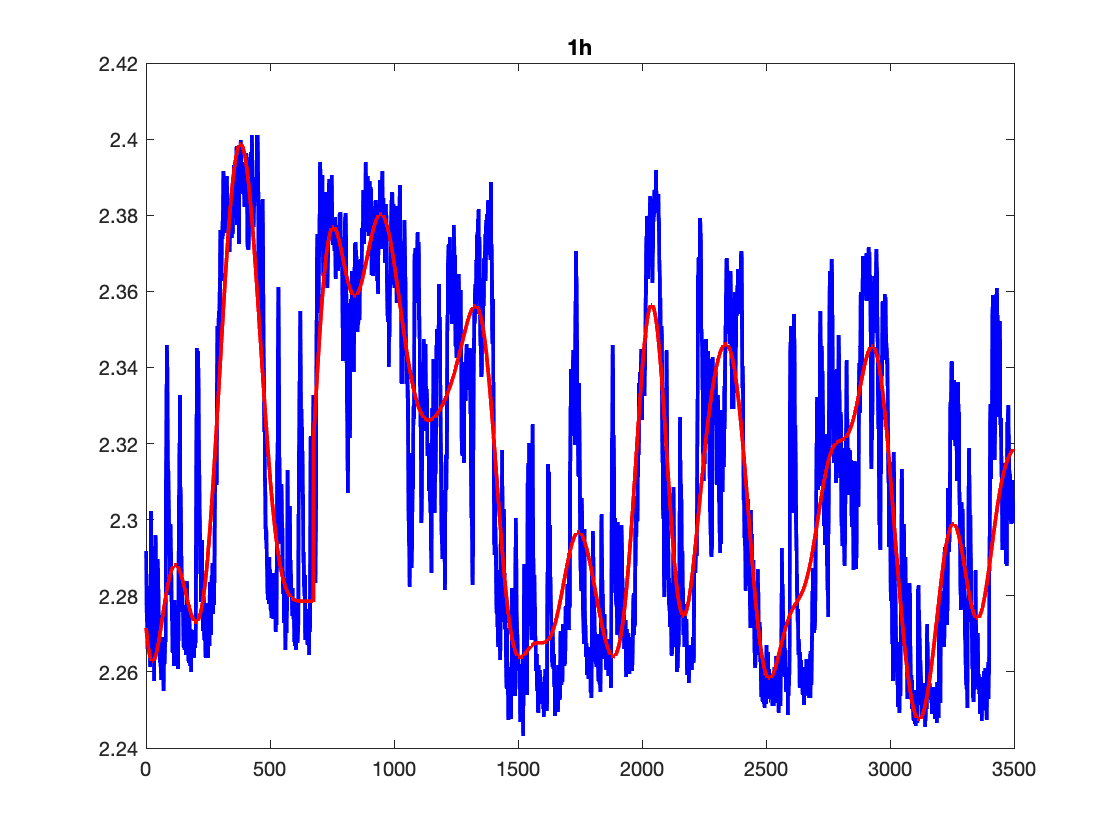

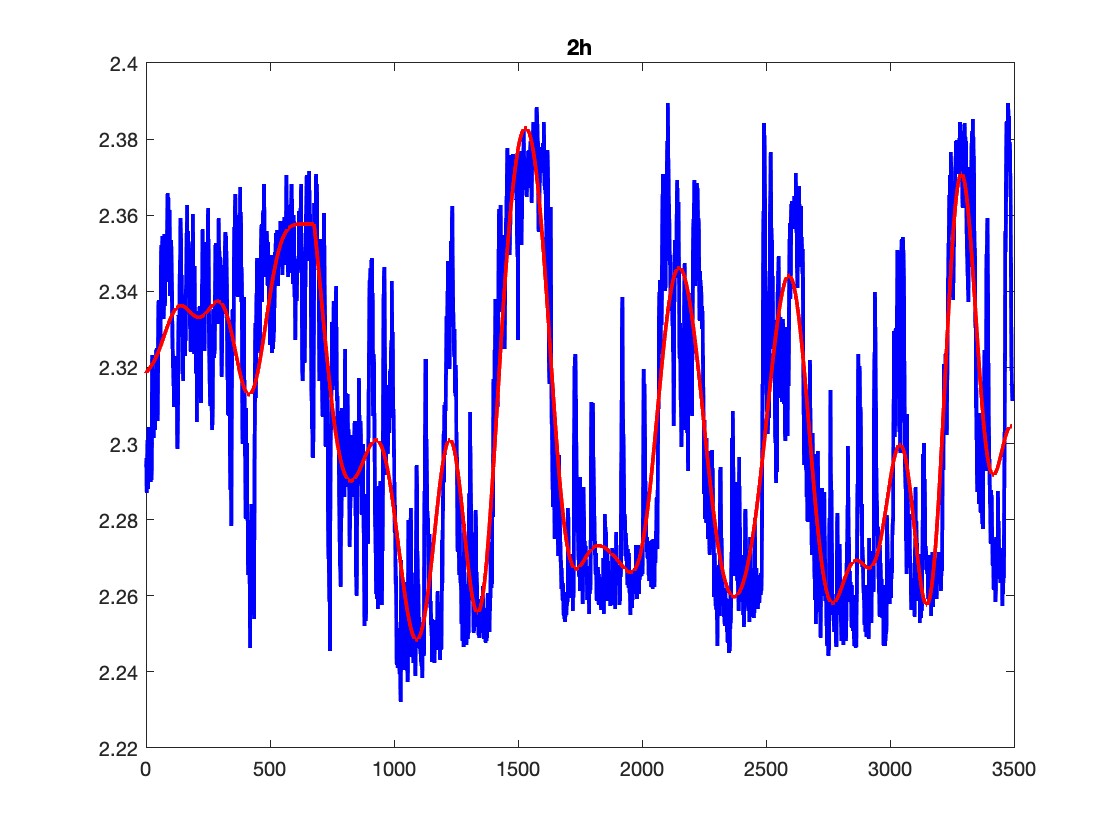

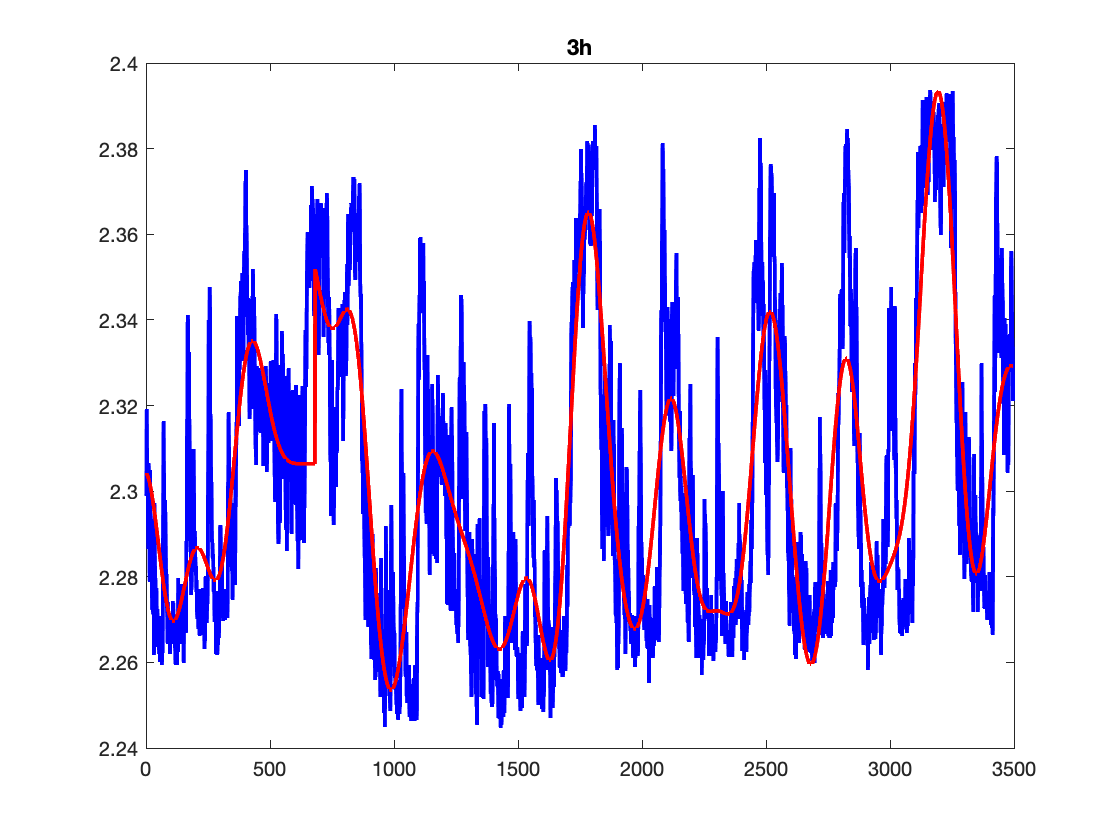

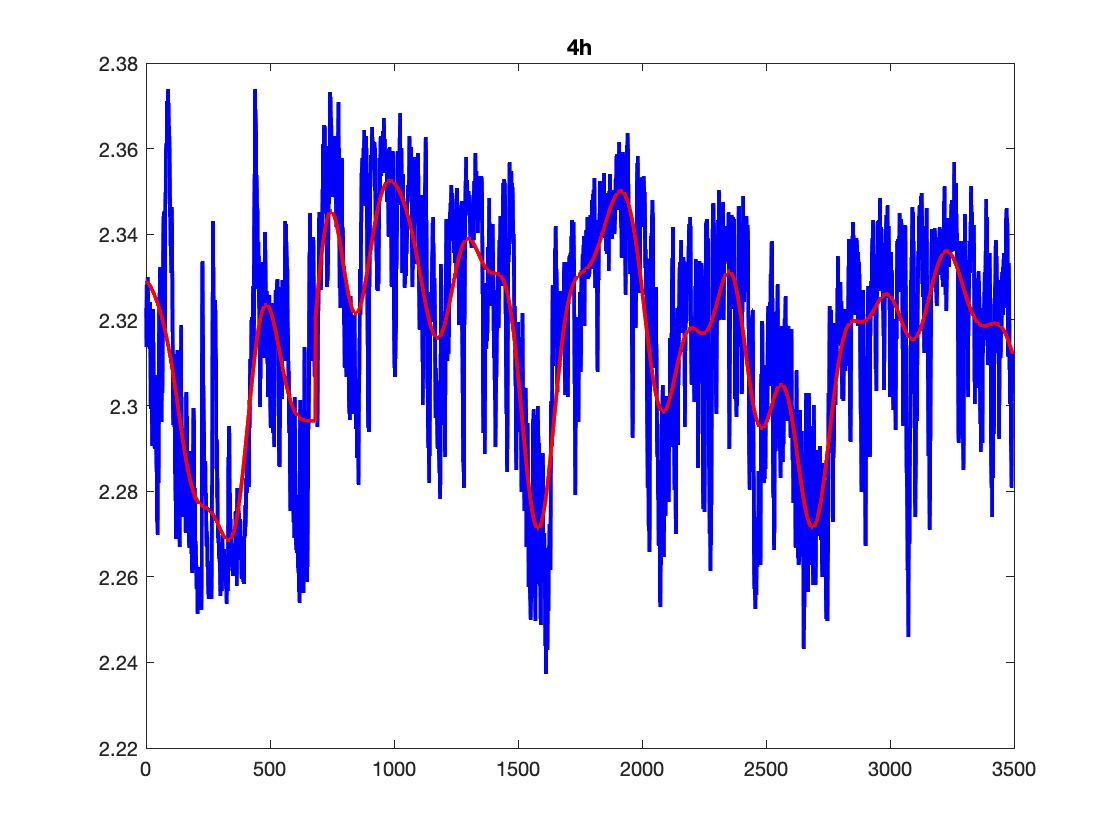

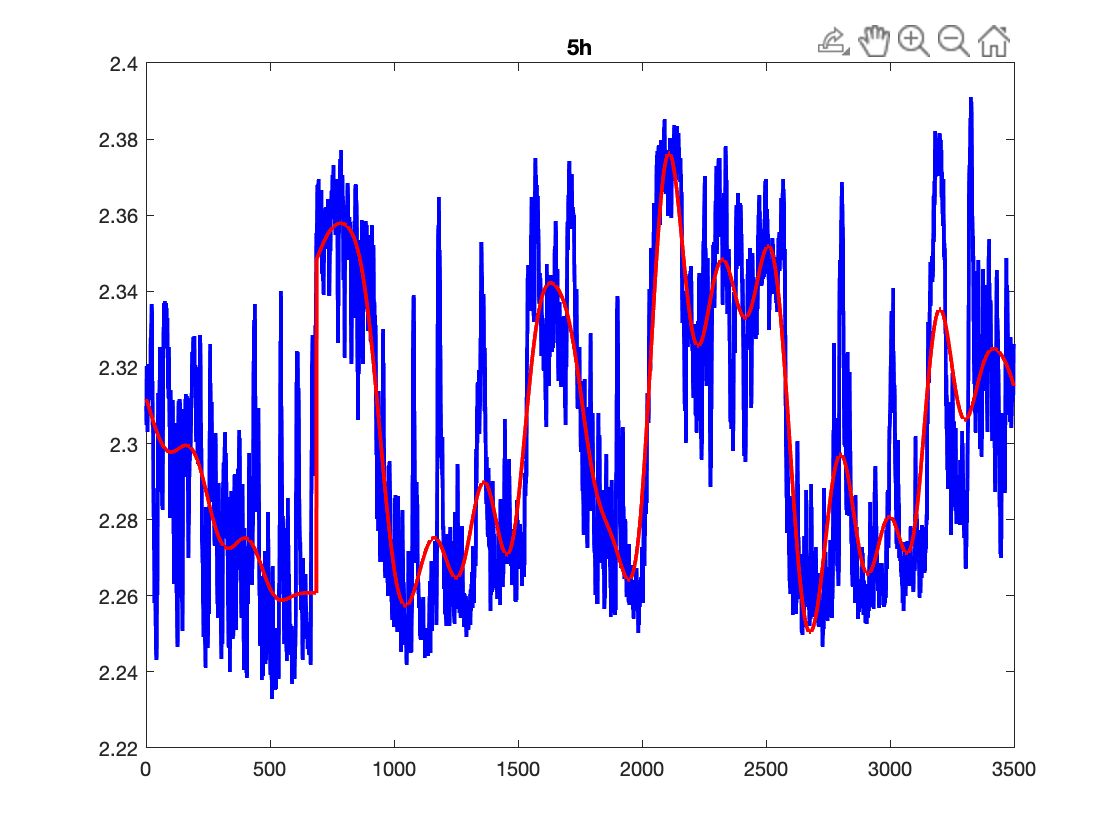

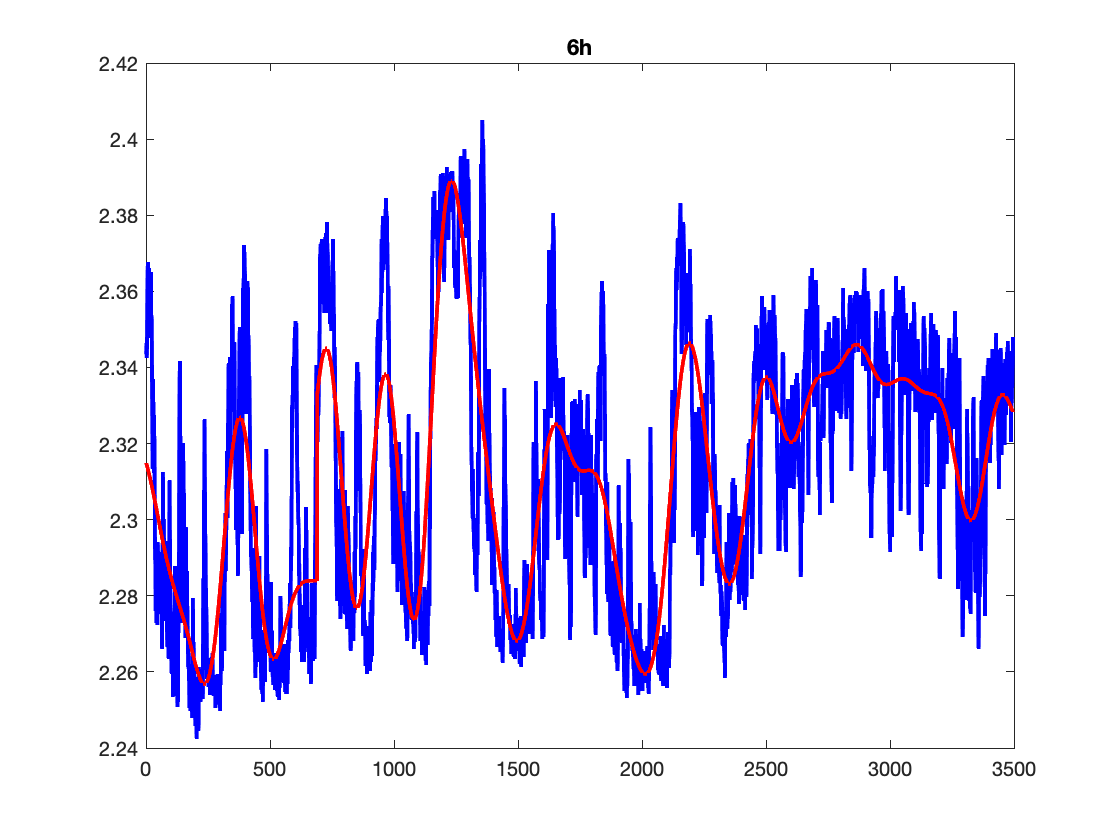

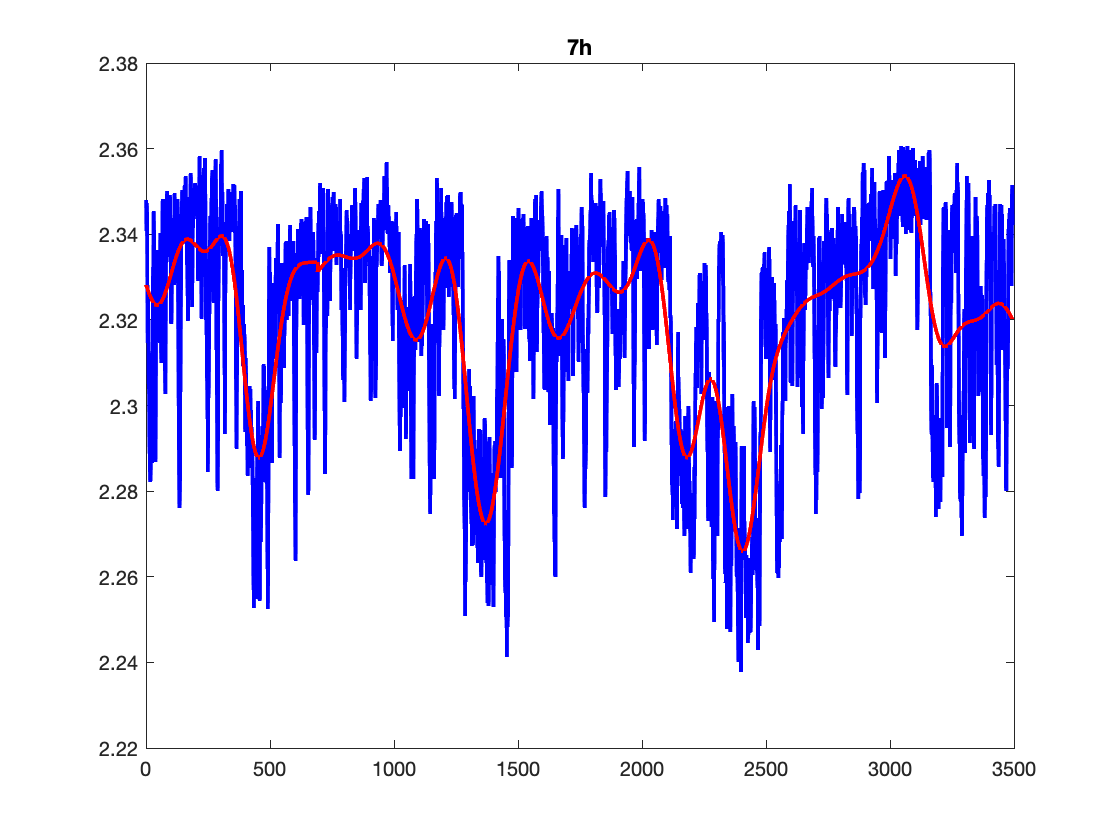

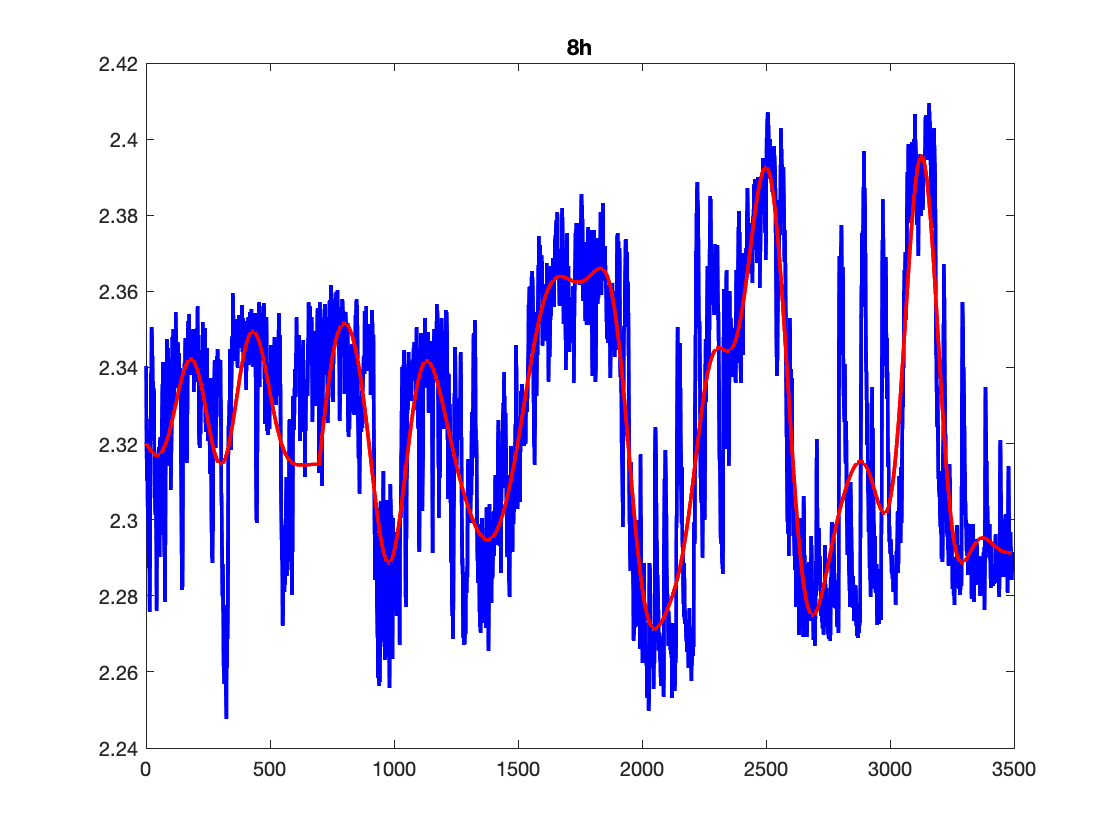

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    
    figure
    plot(tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2,'Color','Blue')
    hold on
    plot(tau_empTrunc_all_DC_darkonly(this_plot_points),'LineWidth',2,'Color','Red')
    title([num2str(i),'h'])
end